# 1222课堂笔记

## **一些例子**

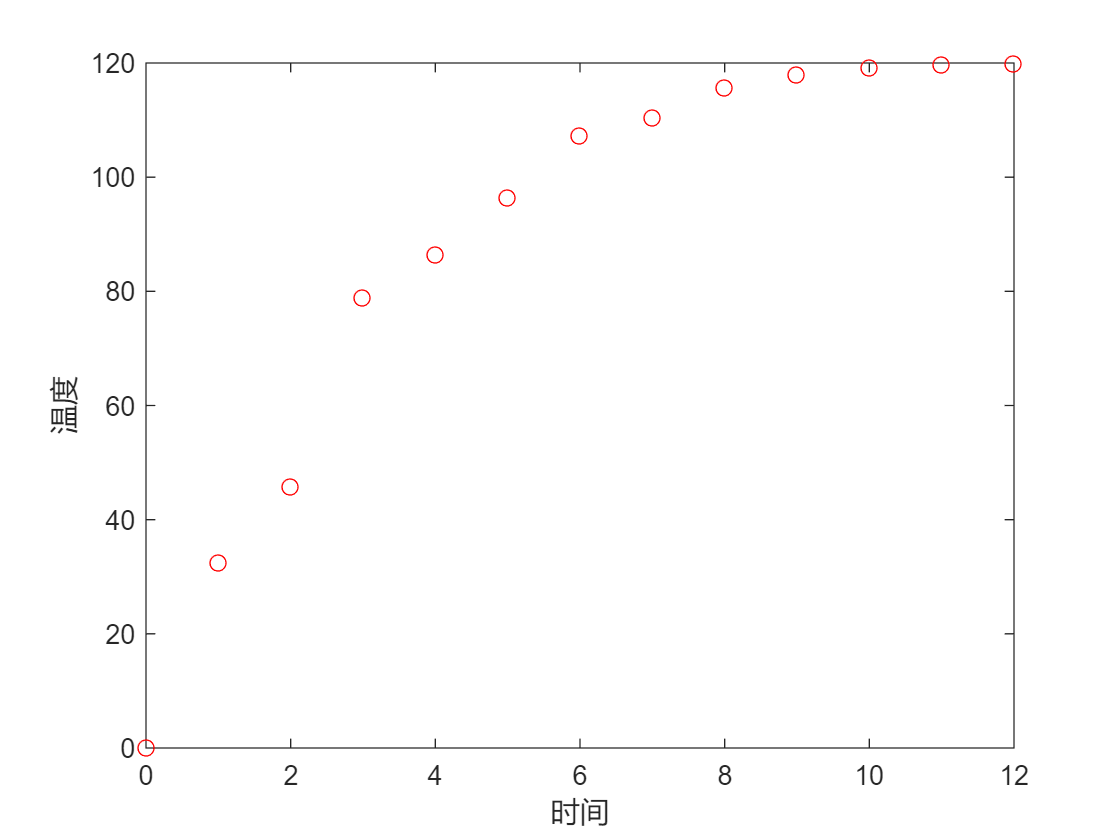

t = 0:12;
T = [0,32.5,45.8,79,86.5,96.5,107.3,110.4,115.7,118,119.2,119.8,120];
plot(t,T,'ro');
xlabel('时间');ylabel('温度');

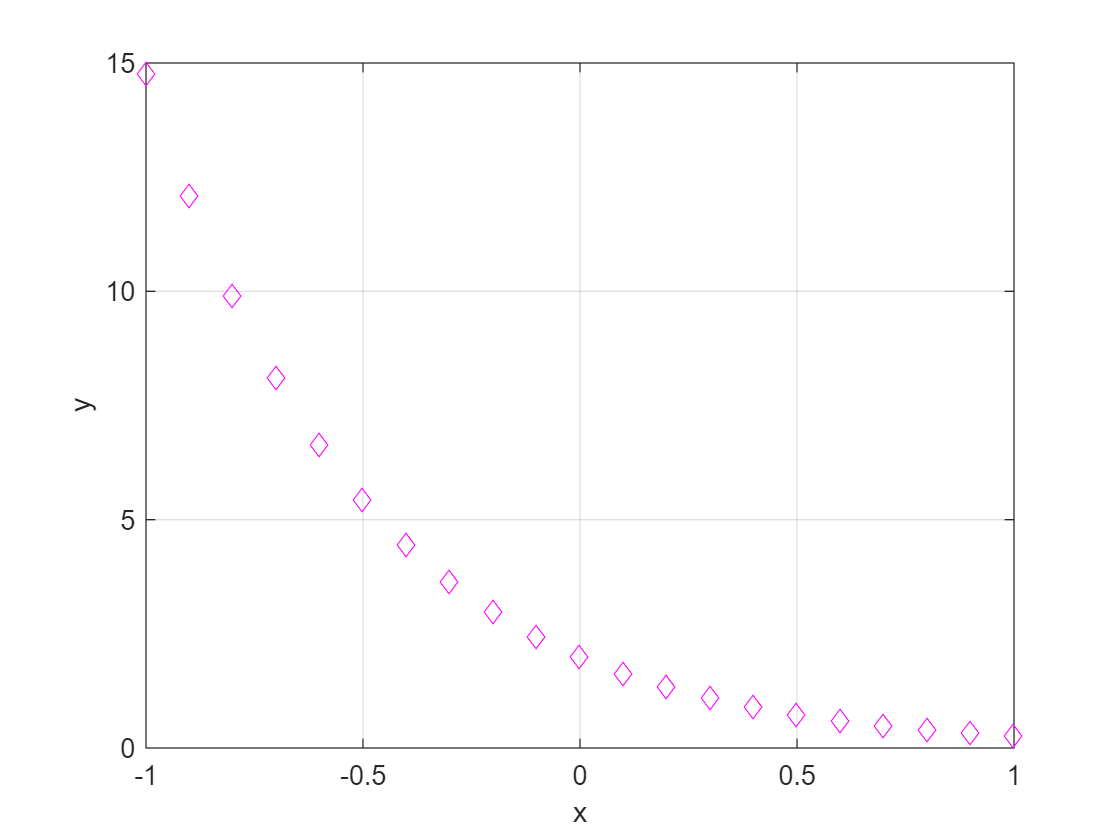

% 离散函数的绘制
x = -1:0.1:1;
y = 2*exp(-2*x);
plot(x,y,'md');
grid on;
xlabel('x');ylabel('y');

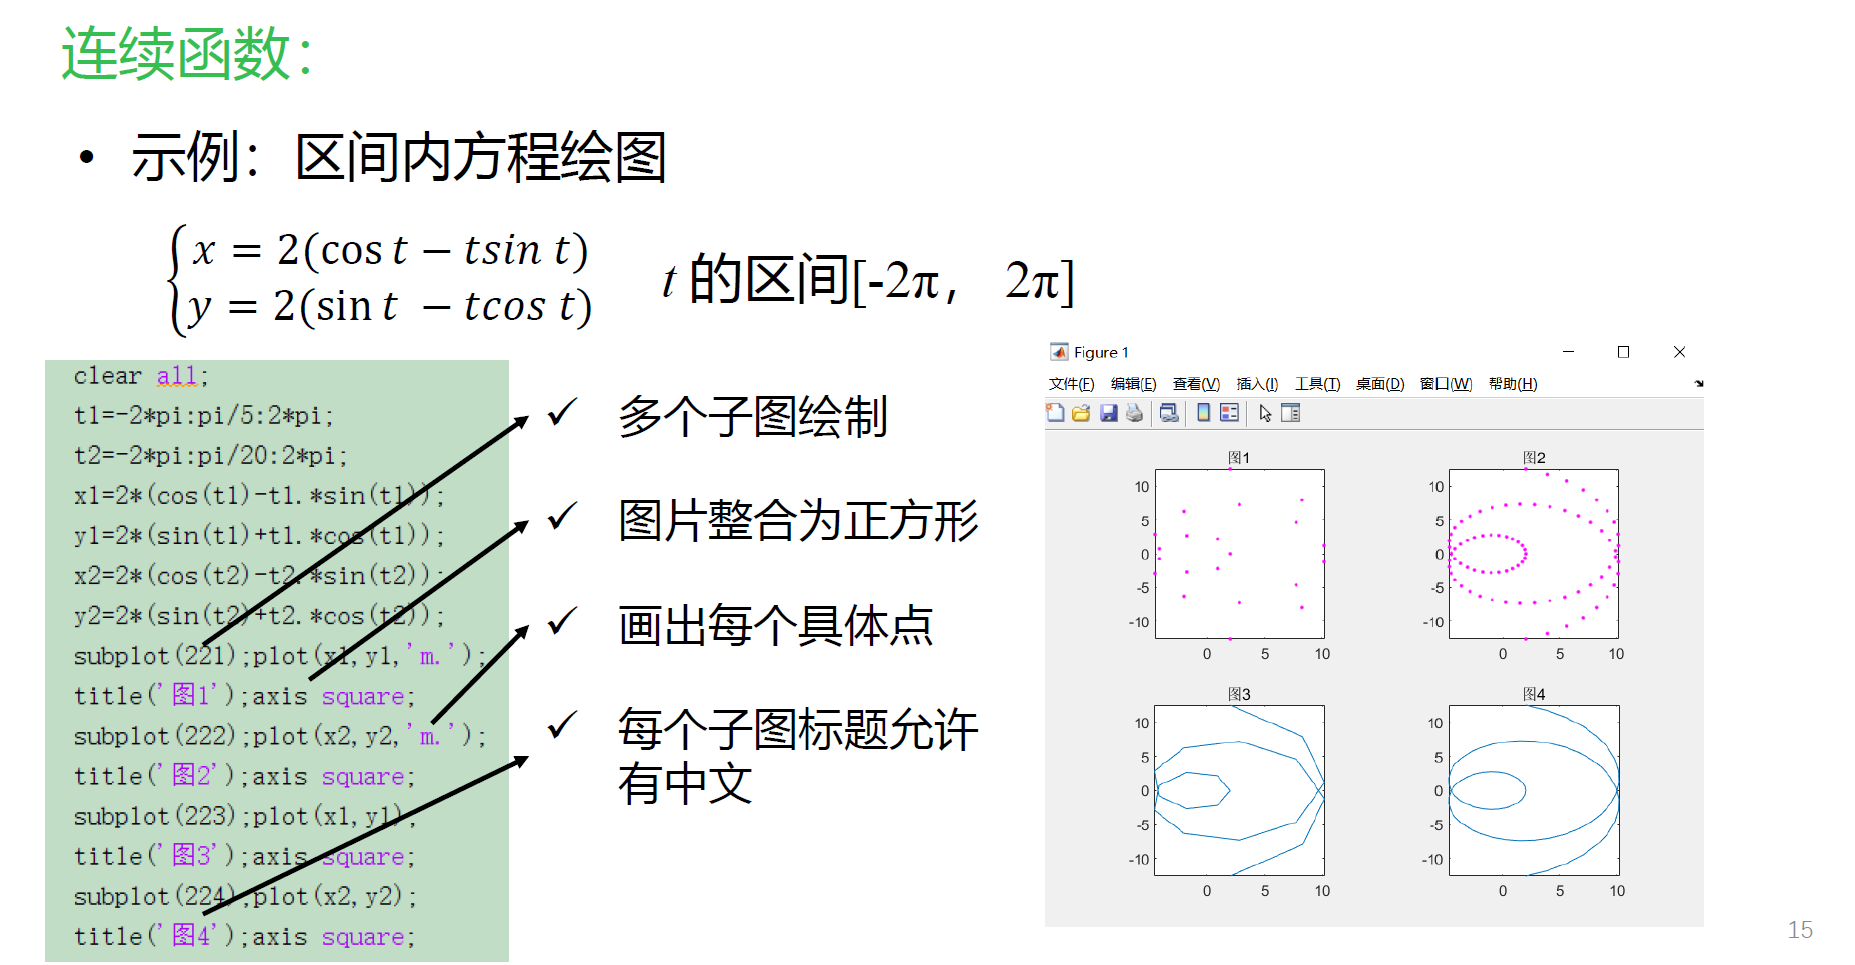

**图例的上下标**

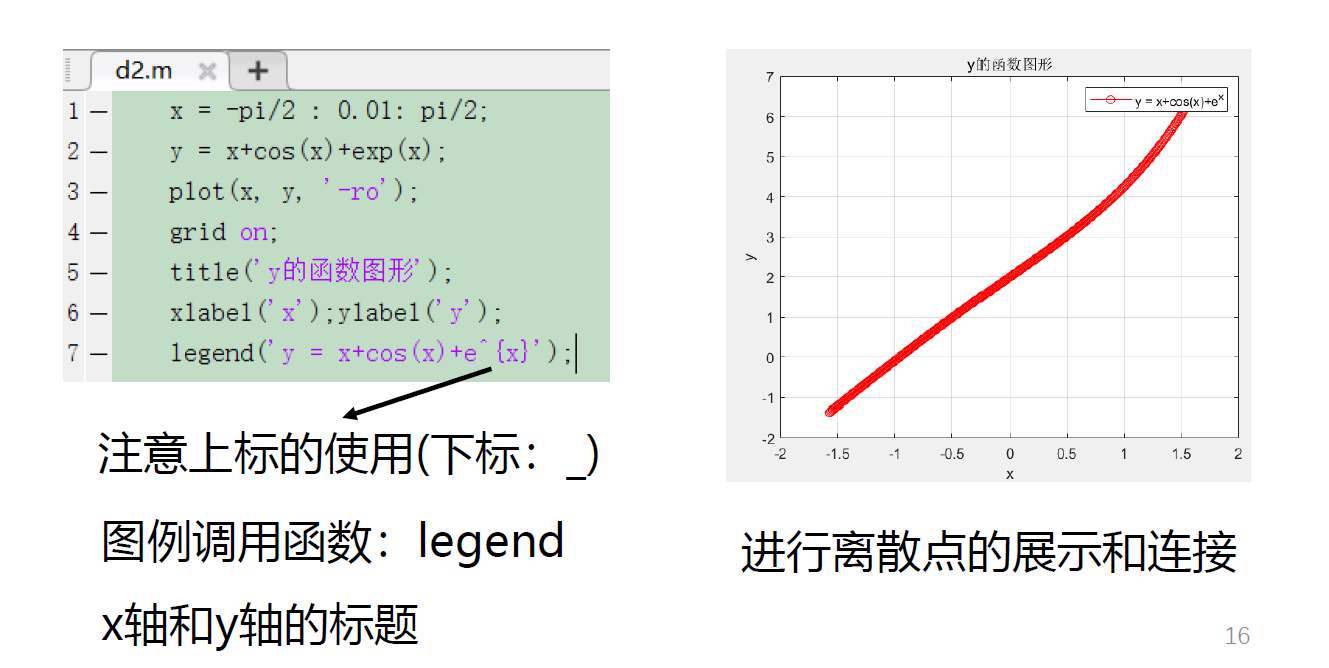

## **plot命令**

关于plot命令的一些参数操作 -- 直接找ppt就行

## line命令

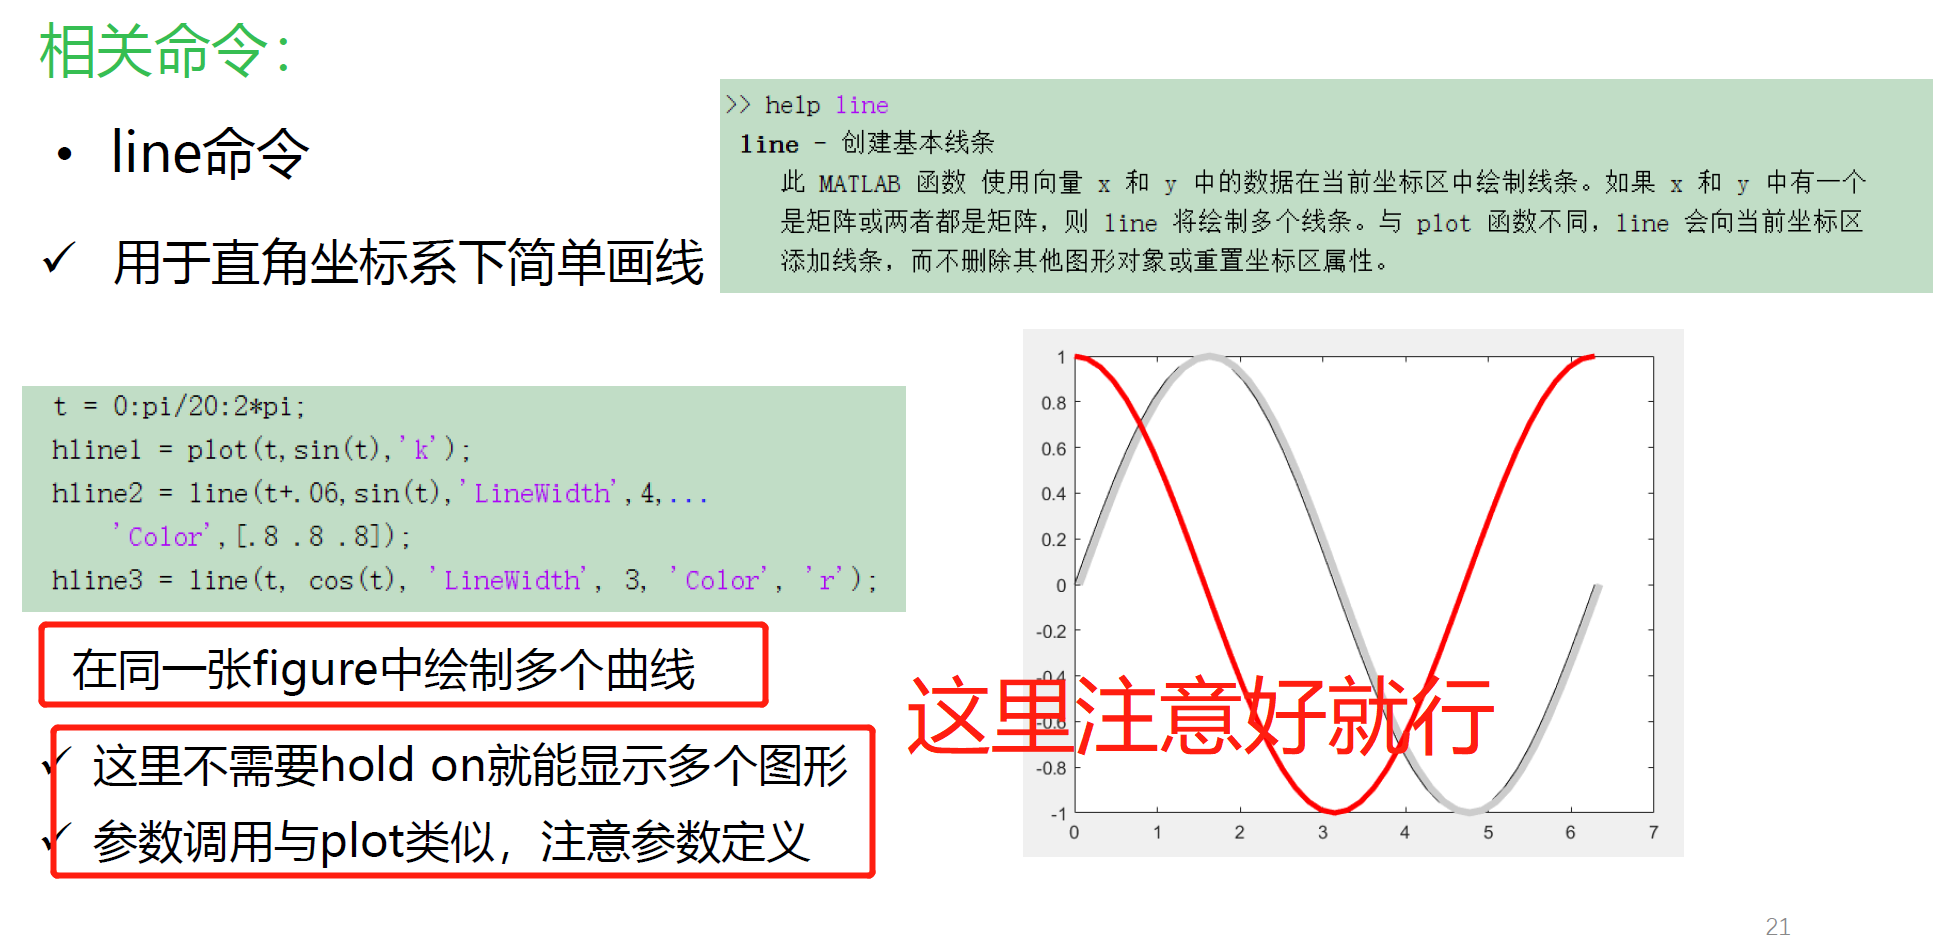

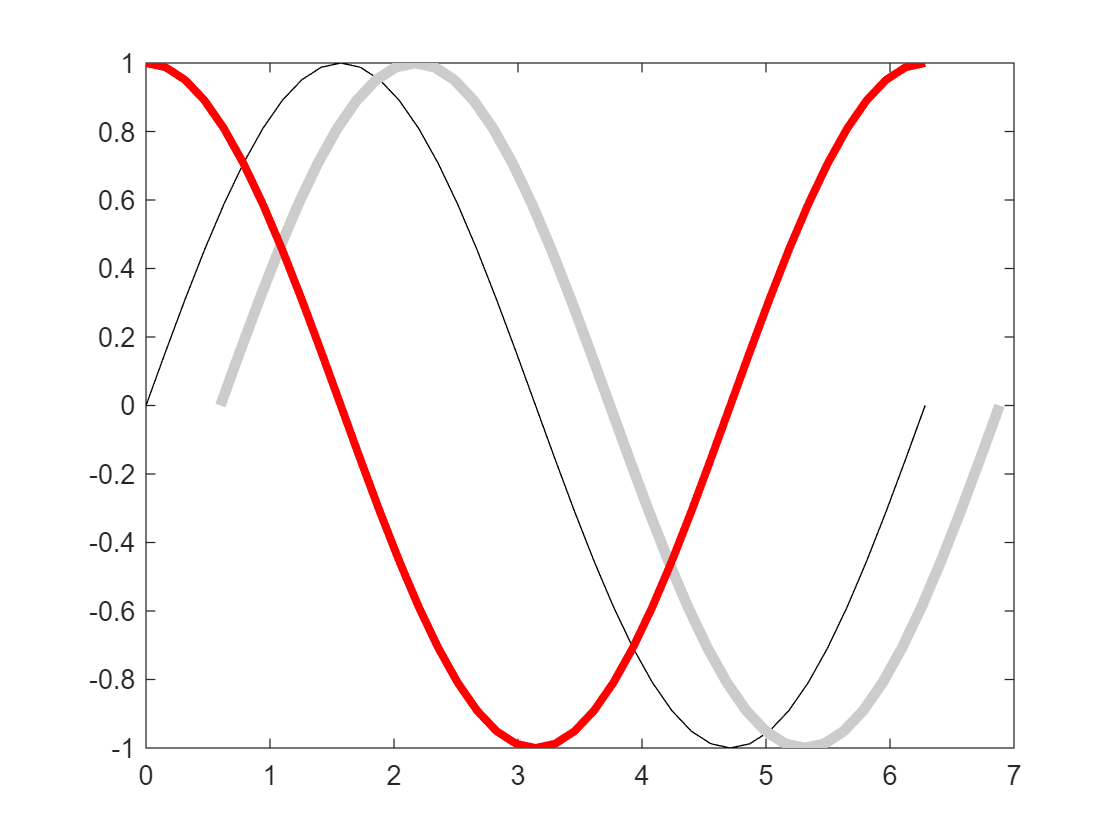

t = 0:pi/20:2*pi;
hline1 = plot(t,sin(t),'k');
hline2 = line(t+.6,sin(t),'LineWidth',4, ...
    'Color',[.8,.8,.8]);
hline3 = line(t,cos(t),'LineWidth',3,'Color','r');

## 轴对数坐标（这个要学一下）semilogx、semilogy、loglog

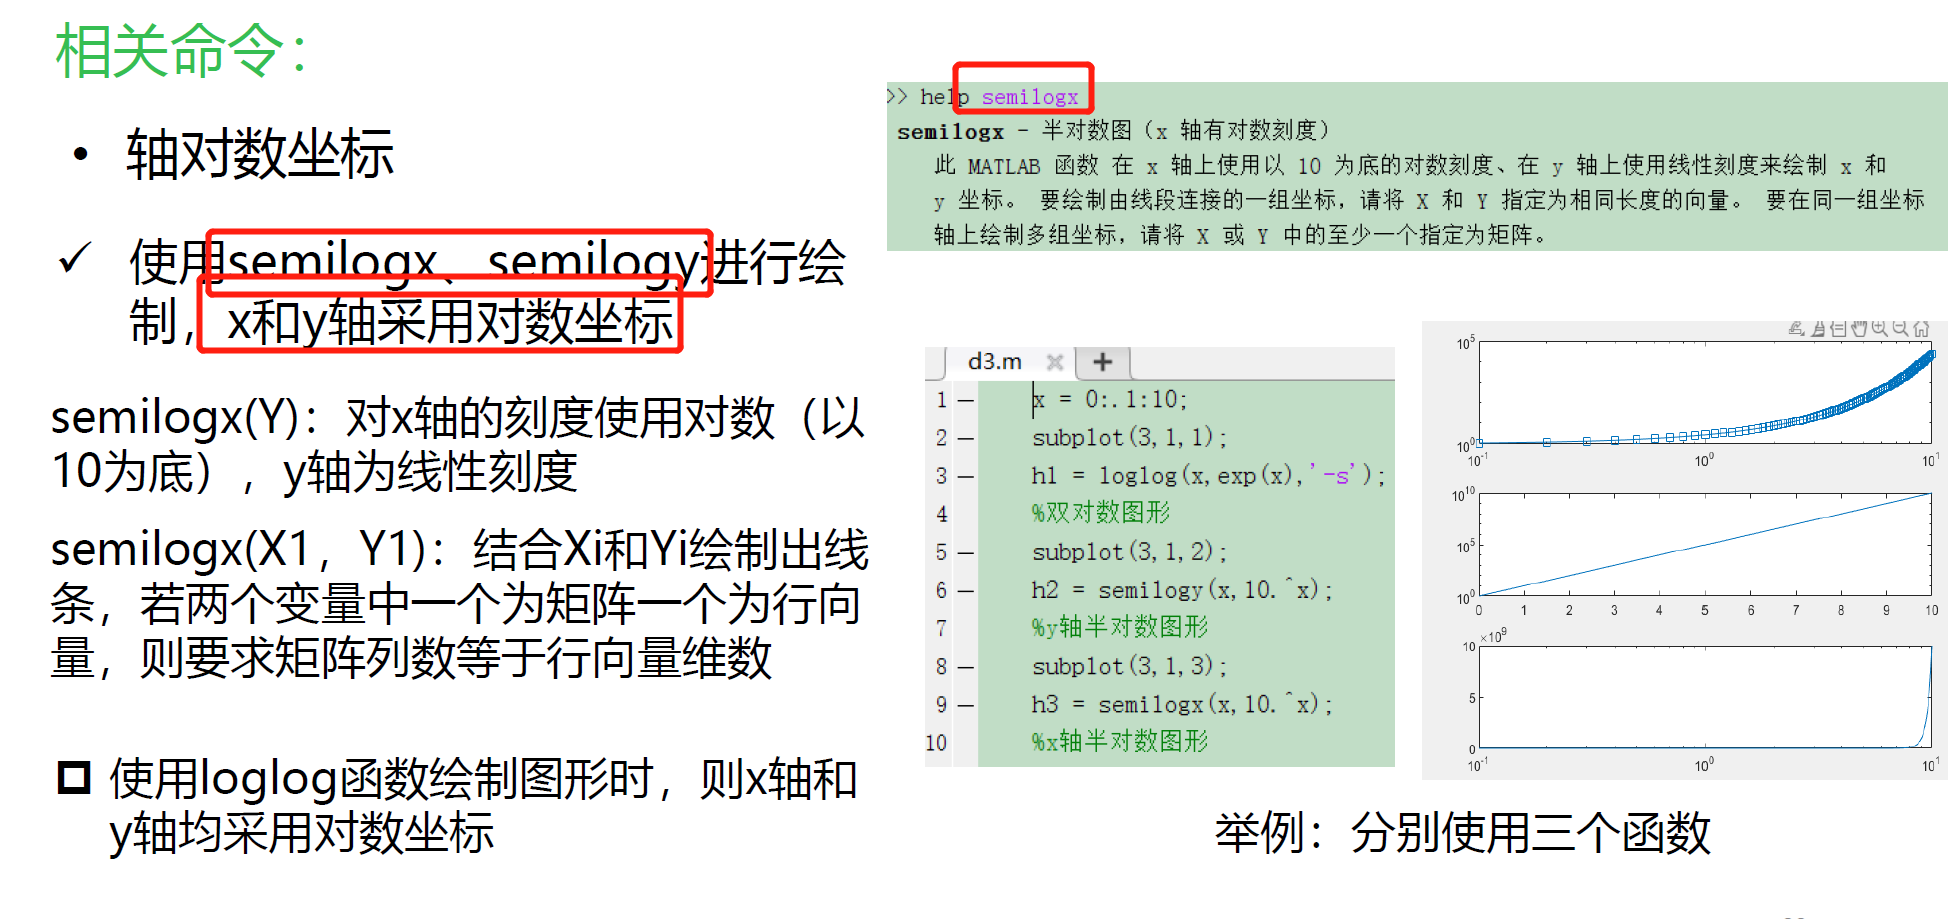

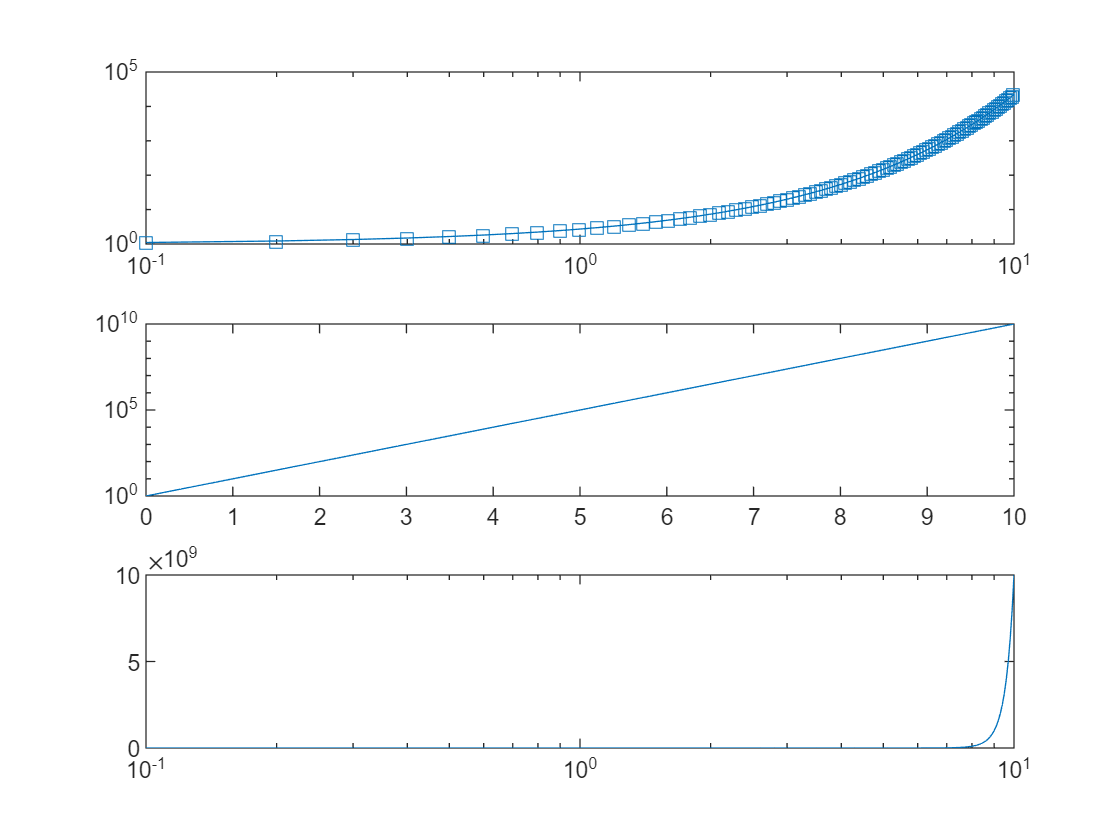

x = 0:.1:10;
subplot(3,1,1);
h1 = loglog(x,exp(x),'-s');% 双对数图形
subplot(3,1,2);
h2 = semilogy(x,10.^x);% y轴半对数图形
subplot(3,1,3);
h3 = semilogx(x,10.^x);% x轴半对数图形

## 双y轴图形（这个要学一下）plotyy

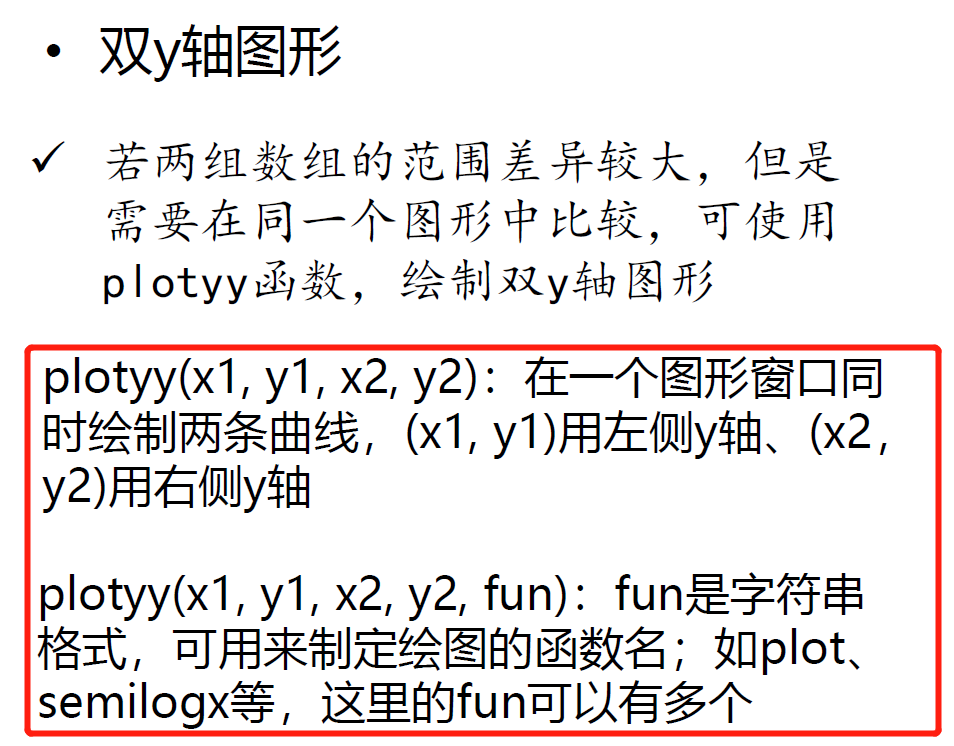

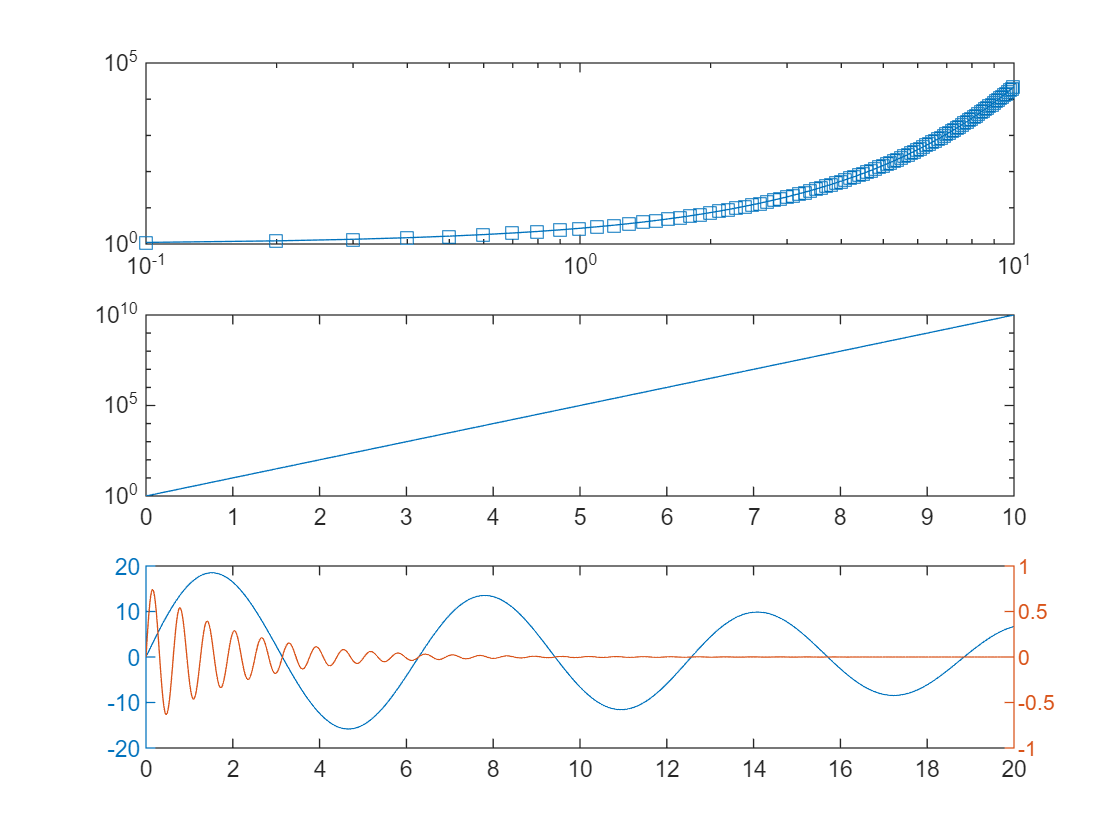

clc;clear all;
x = 0:0.01:20;
y1 = 20*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
[AX,H1,H2] = plotyy(x,y1,x,y2,'plot'); % 返回去的其实是属性，如果只画图的话就不用返回值了

## subplot

会用了，如果还有复杂的功能不会，查一下ppt（先查百度，再查ppt，再查文档）

## 例子

在同一个figure中绘制多个曲线图，并给出图示

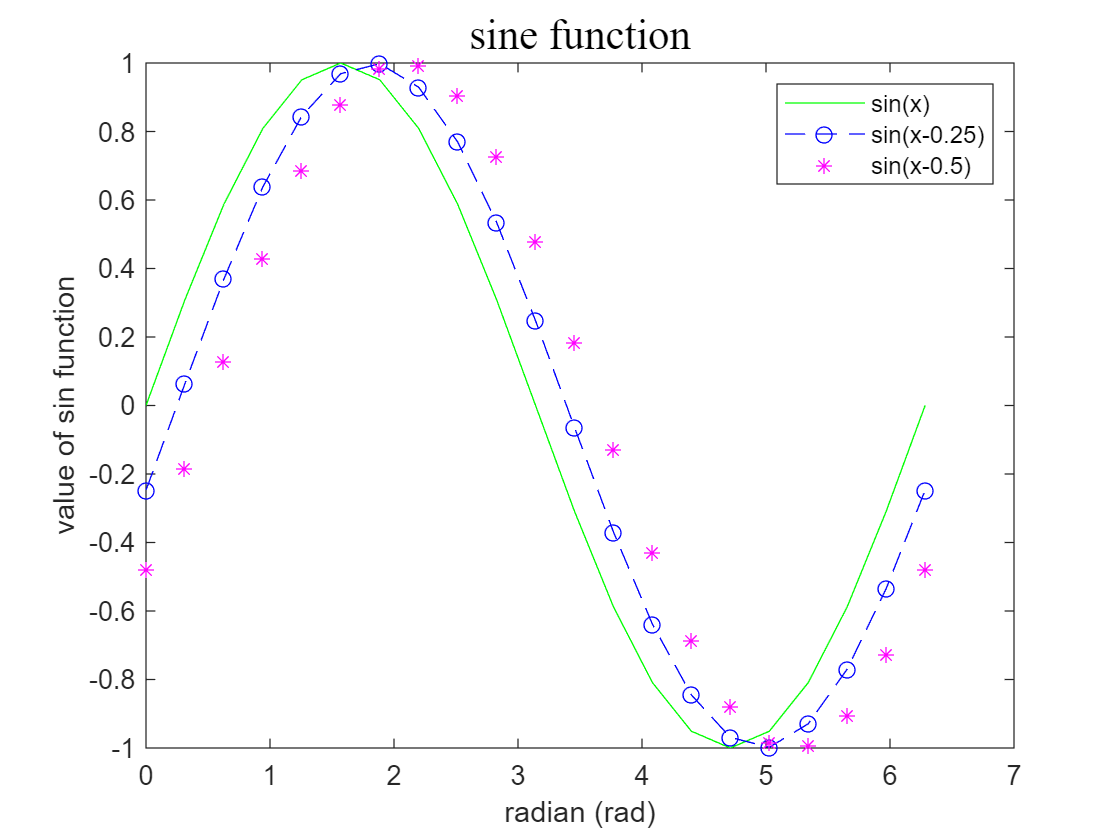

x = 0:pi/10:2*pi;
y1 = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
figure;
plot(x,y1,'g',x,y2,'b--o',x,y3,'m*');
title('sine function','FontName','Times New Roman','FontSize',16);
xlabel('radian (rad)');
ylabel('value of sin function');
legend('sin(x)','sin(x-0.25)','sin(x-0.5)');

## 坐标轴说明

### 注意数据在坐标轴上的差距！

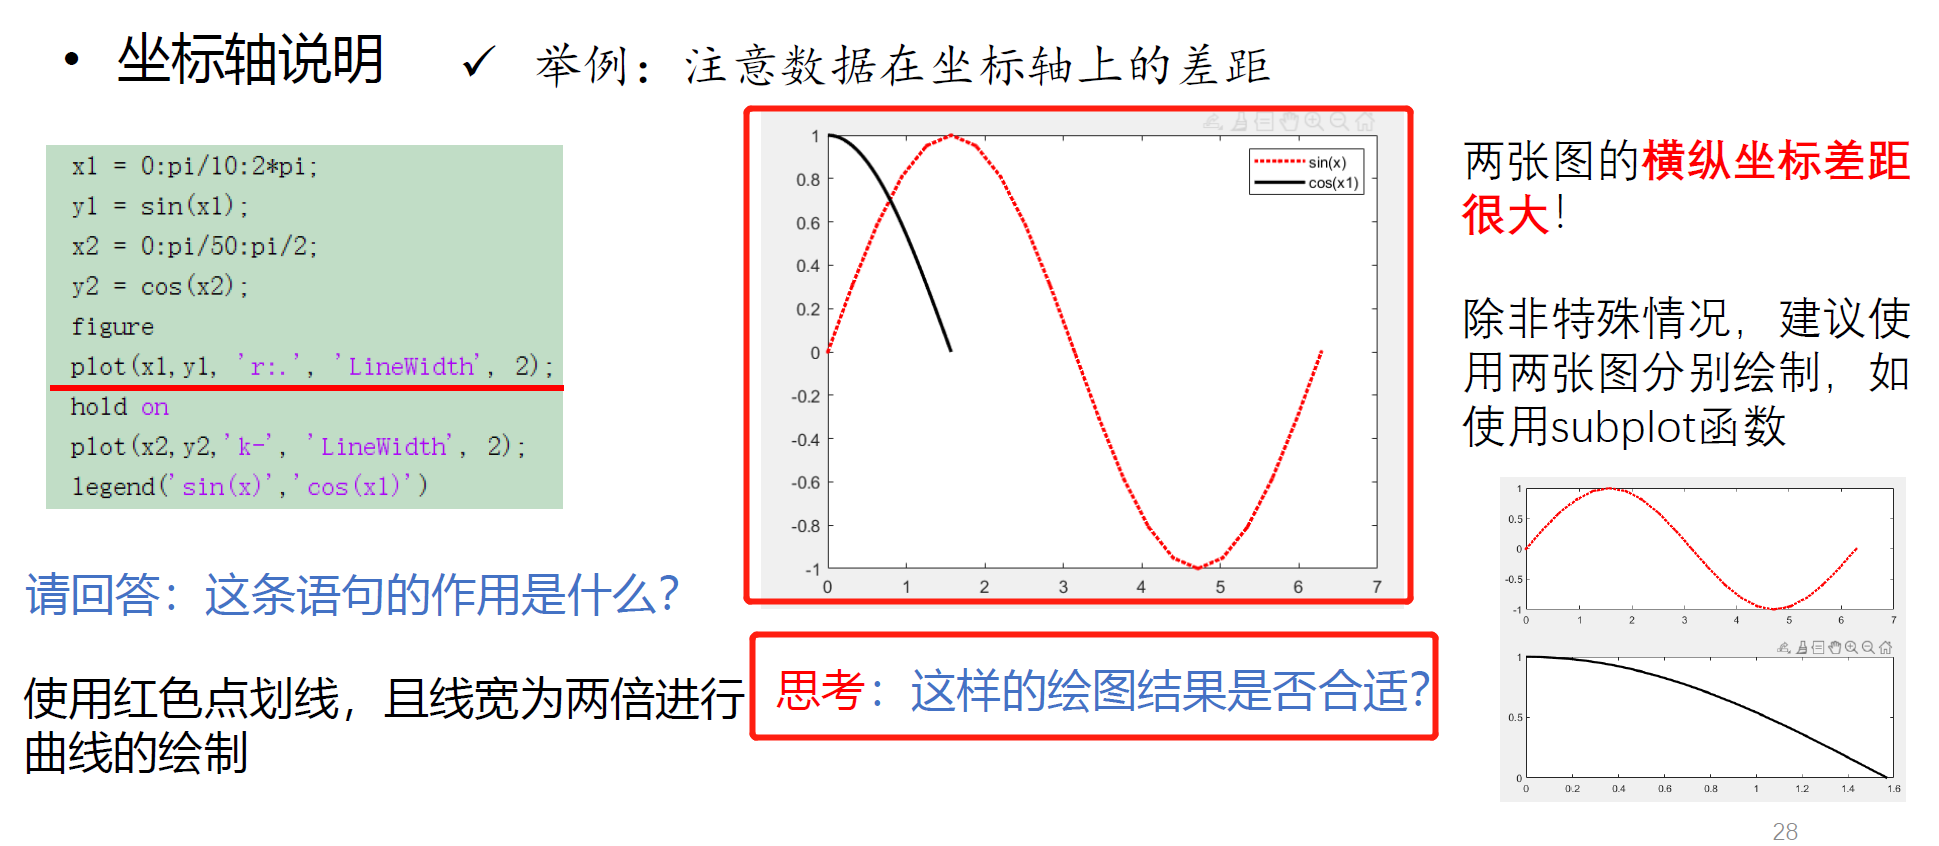

如果出现上述情况，建议使用subplot函数分开画。

## 相关命令

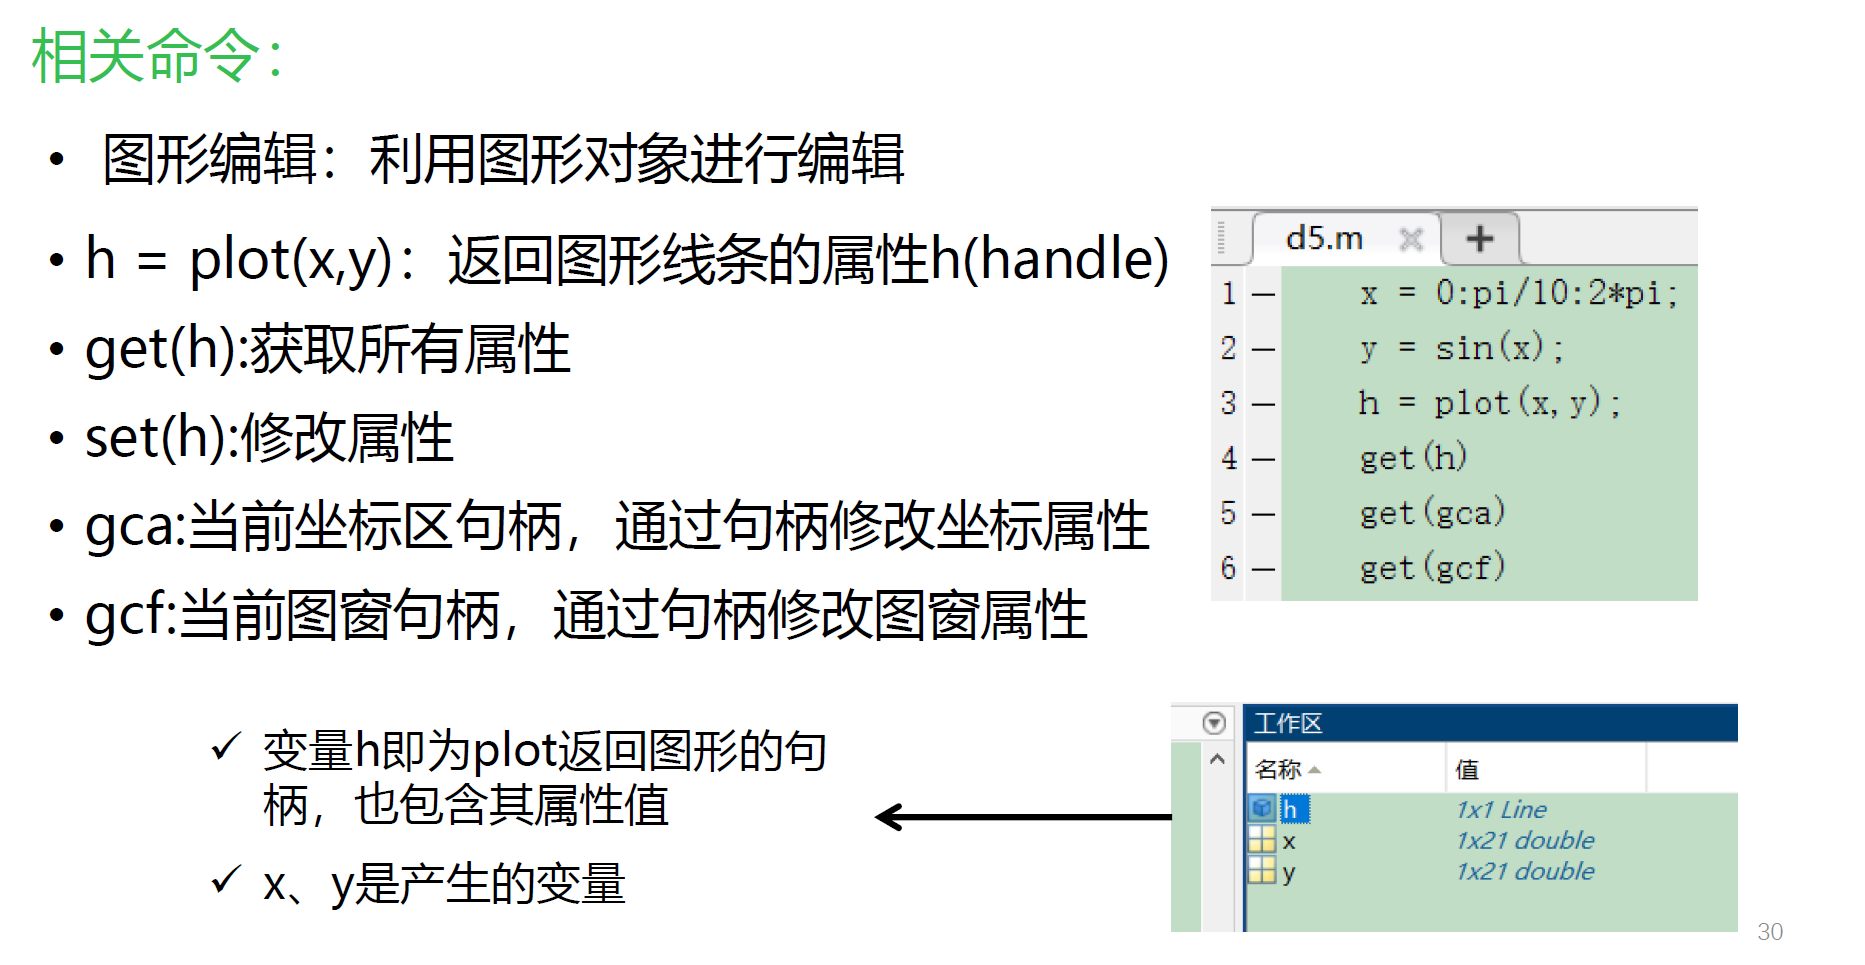

## 坐标轴参数编辑例子（学一下）

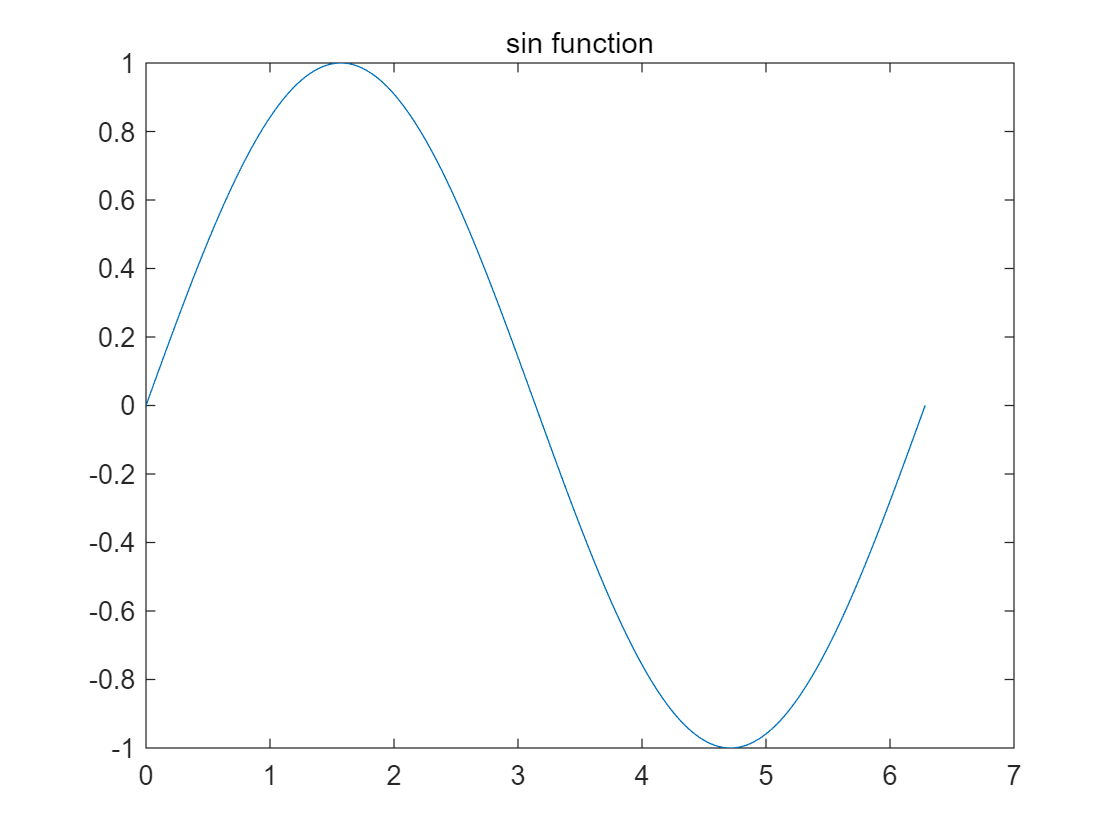

x = 0:pi/100:2*pi;
y = sin(x);
h = plot(x,y);
title("sin function");

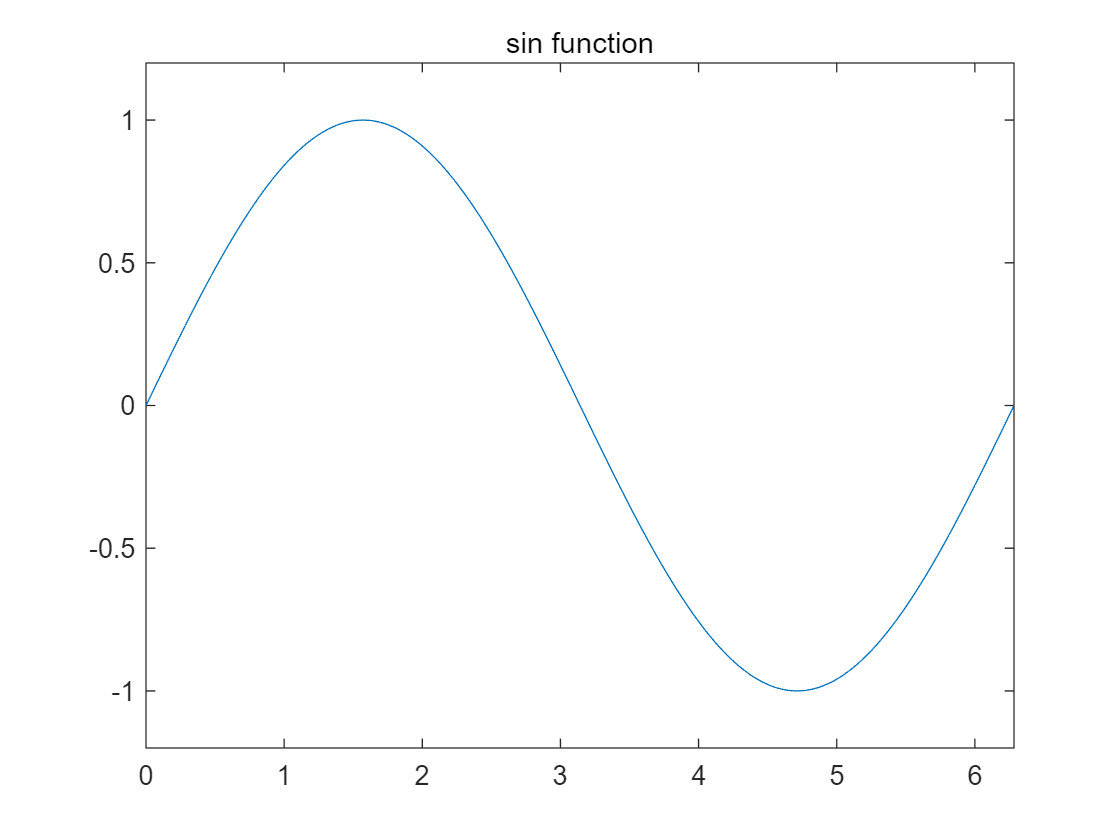

% 思考，如何修改坐标轴，使得整个线条沾满边框？
x = 0:pi/100:2*pi;
y = sin(x);
h = plot(x,y);
title("sin function");
% set(gca,'XLim',[0,2*pi]);
% set(gca,'YLim',[-1.2,1.2]);
% 或者用
xlim([0,2*pi]);
ylim([-1.2,1.2]); % 也是同样的效果

## 字体的参数编辑（学一下）

% set(gca,'FontSize',16);
% 使用句柄可以把整个图形中的字体大小全部调节
% 注意，是全部调节！

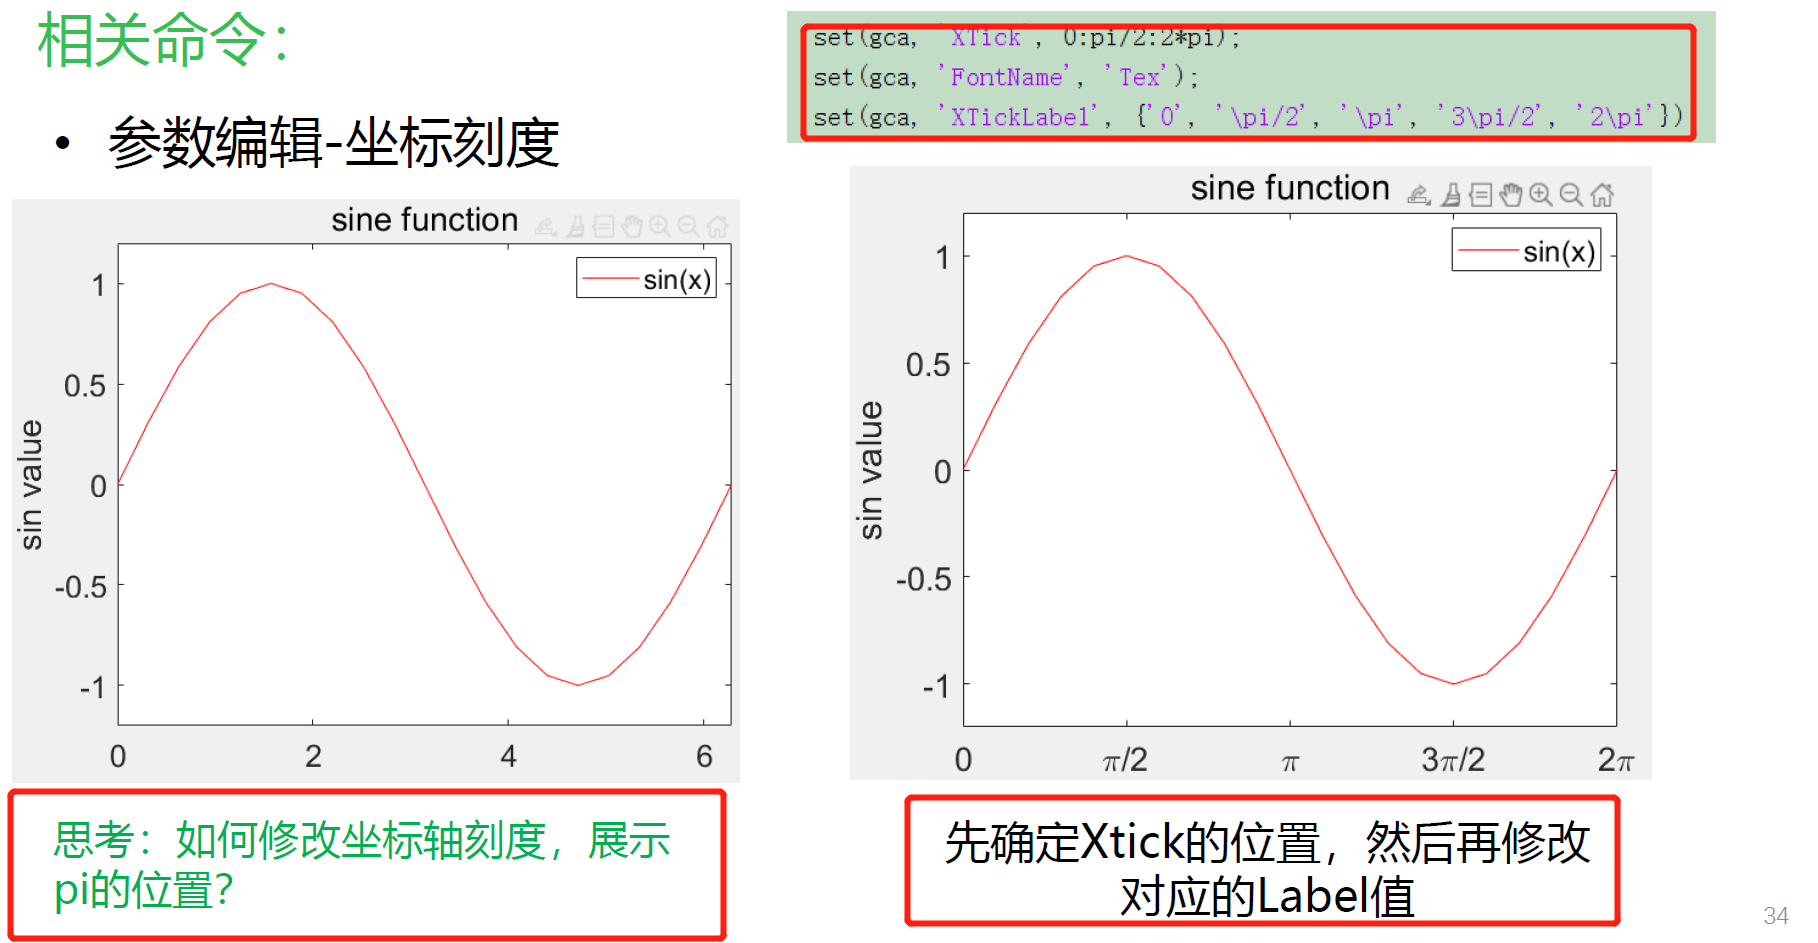

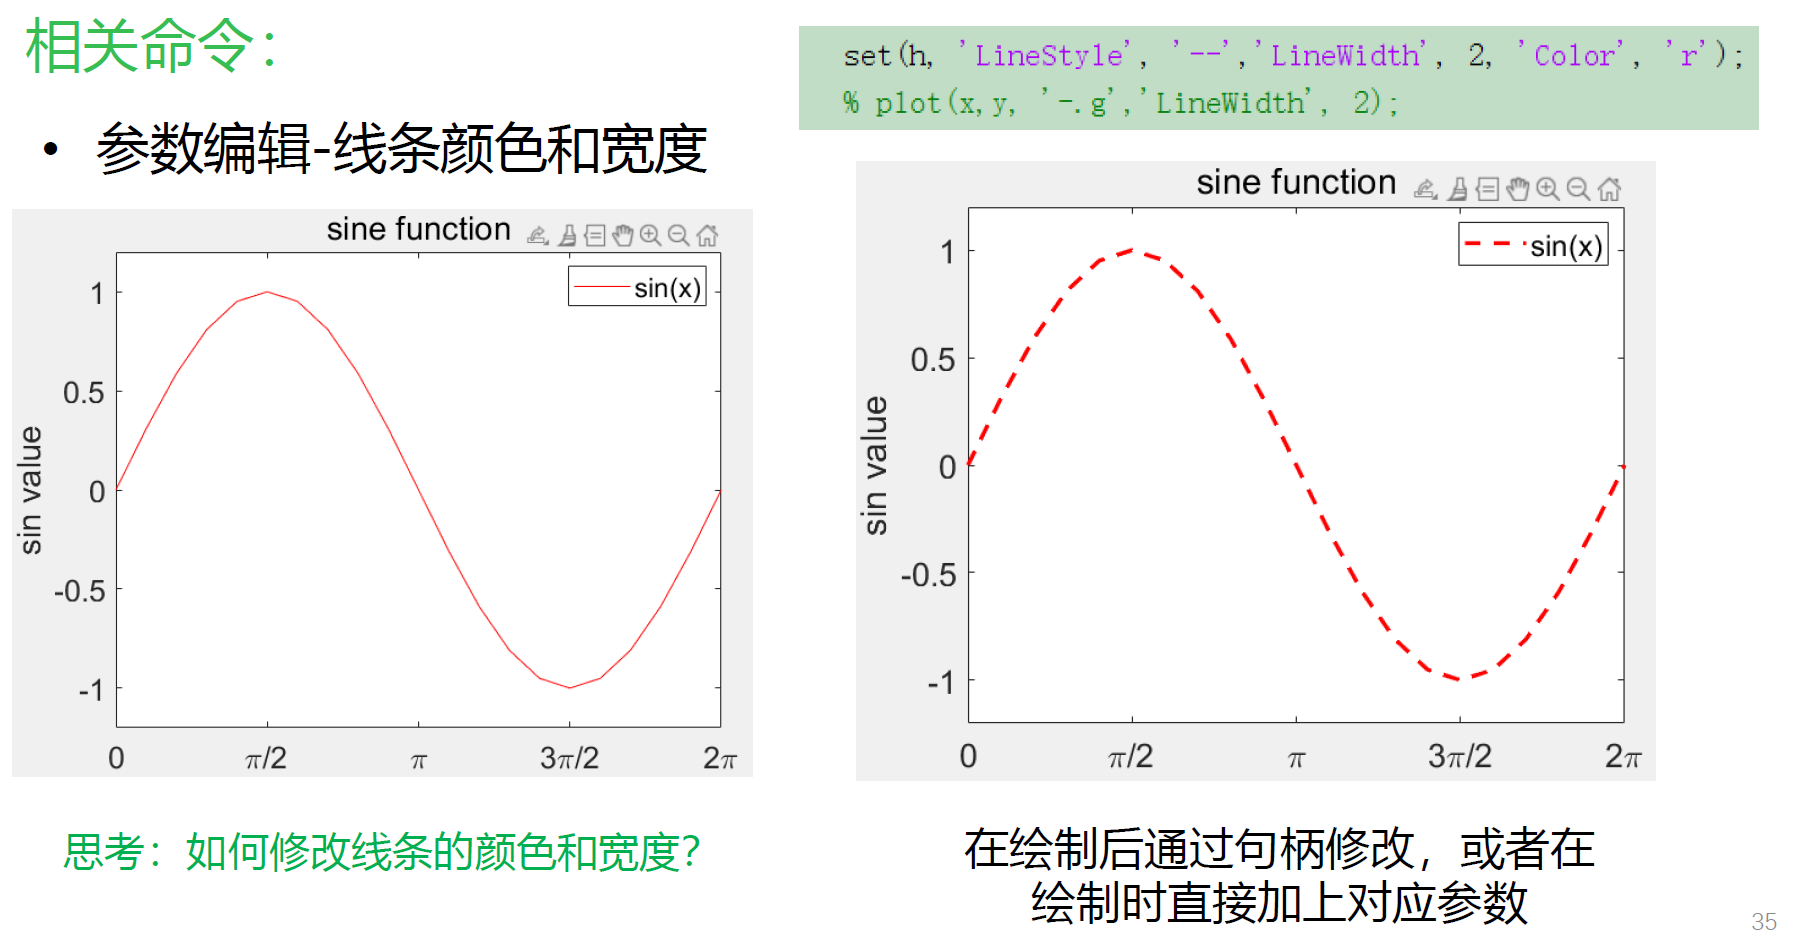

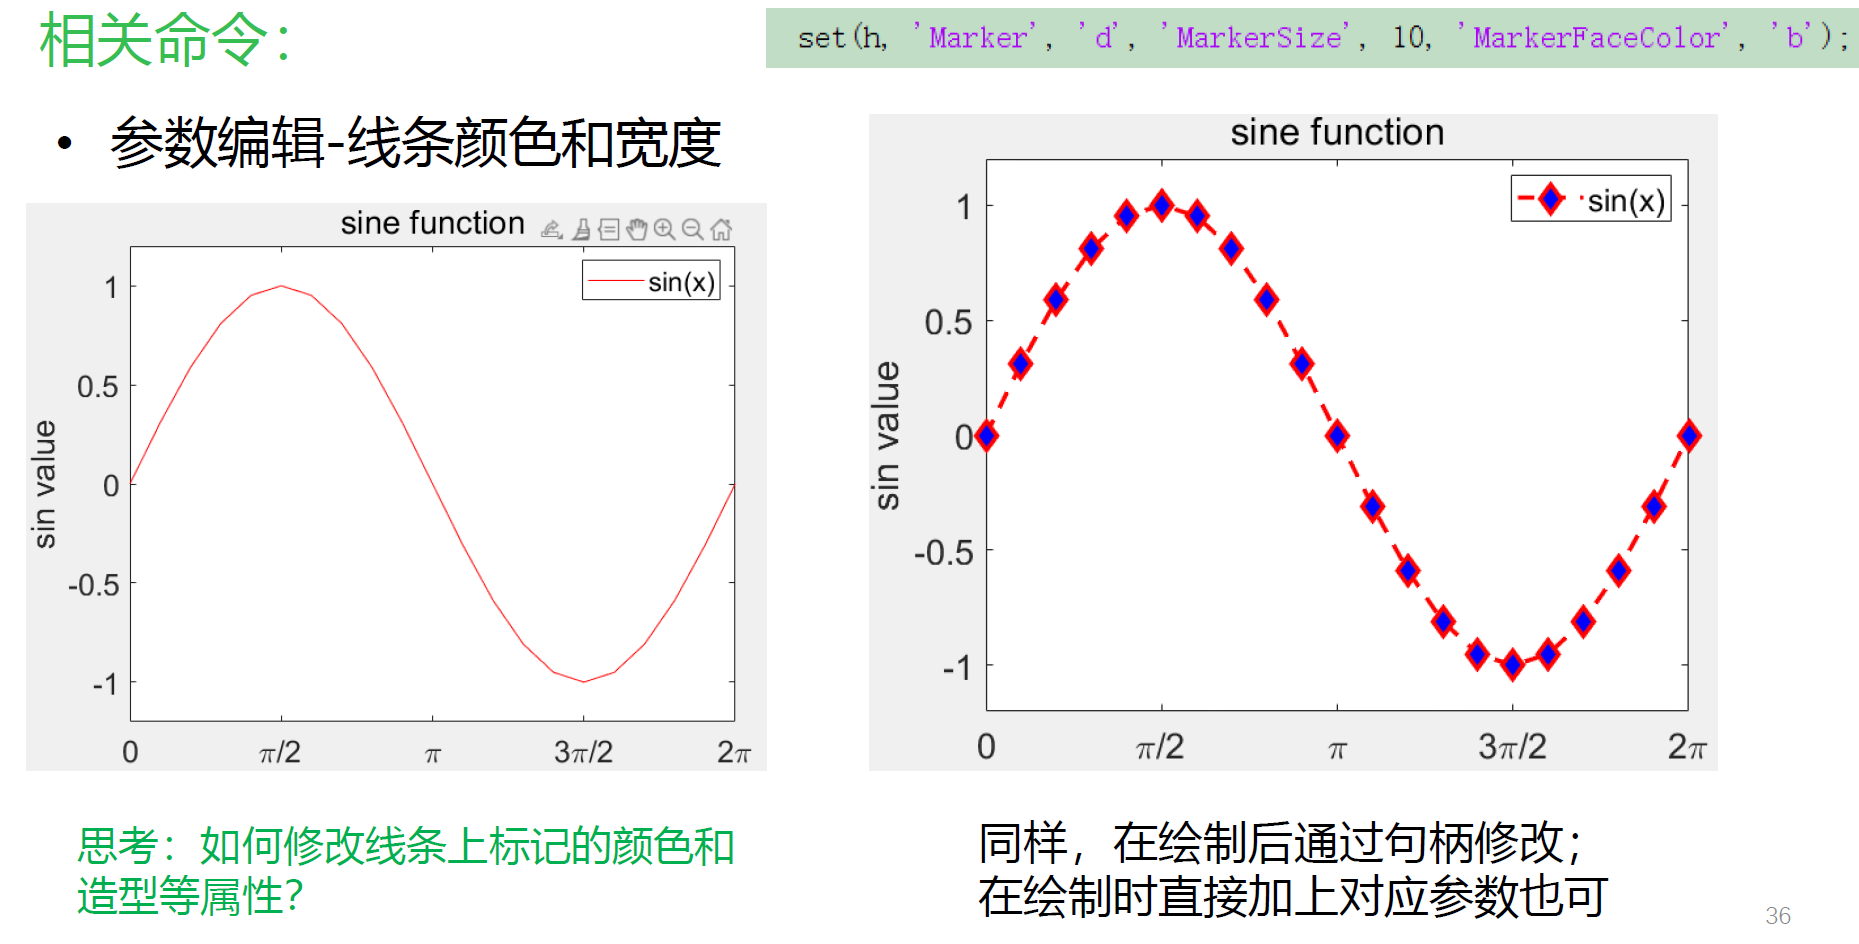

## 图形的保存

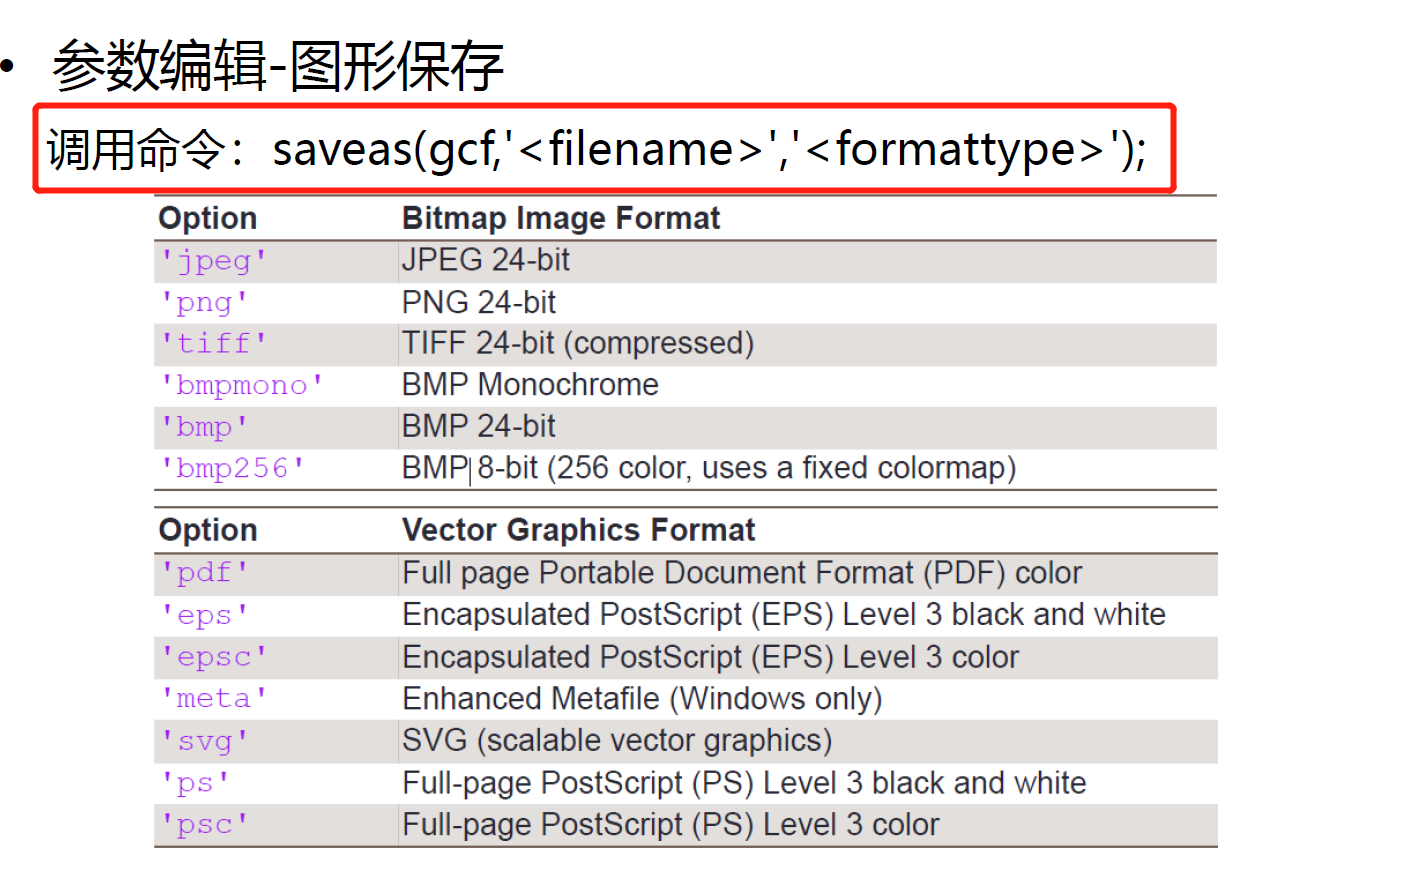

## 直方图 histogram

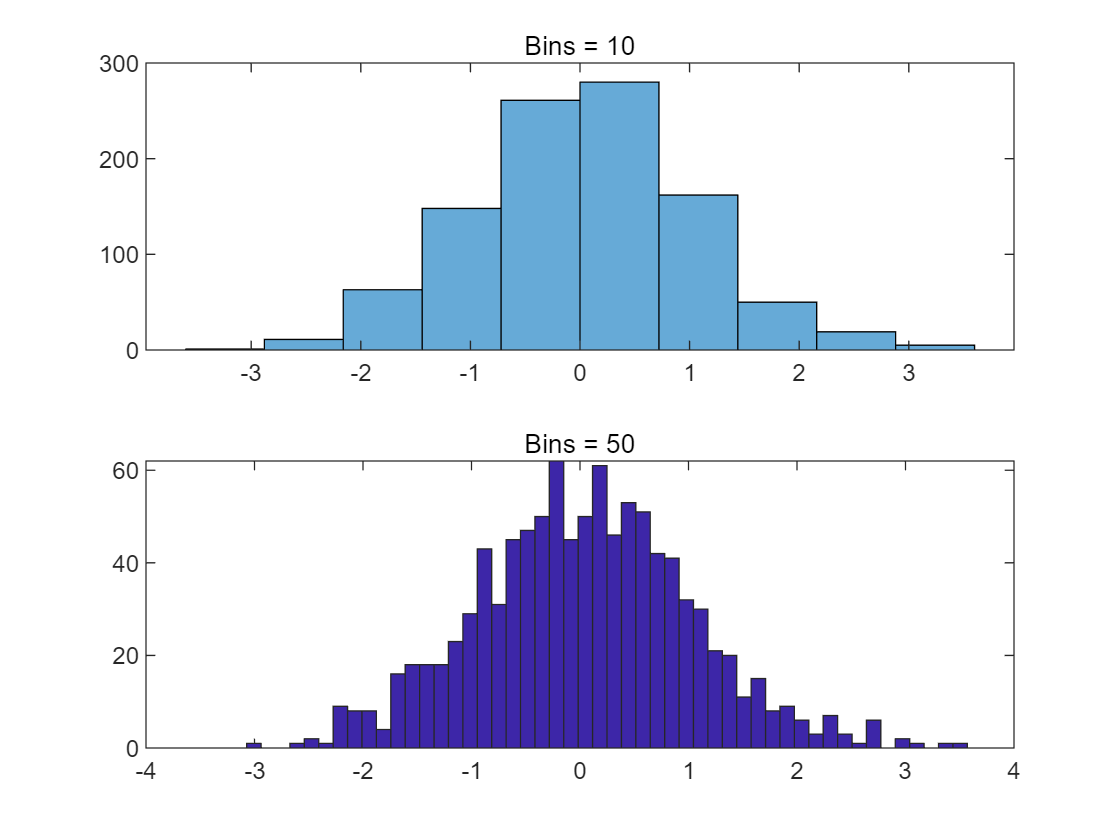

% 生成一个1x1000满足正态分布的随机数向量
y = randn(1,1000);
subplot(2,1,1);
histogram(y,10);
title('Bins = 10');
subplot(2,1,2);
hist(y,50);
title("Bins = 50");

## 柱状图/条形图 bar/bar3

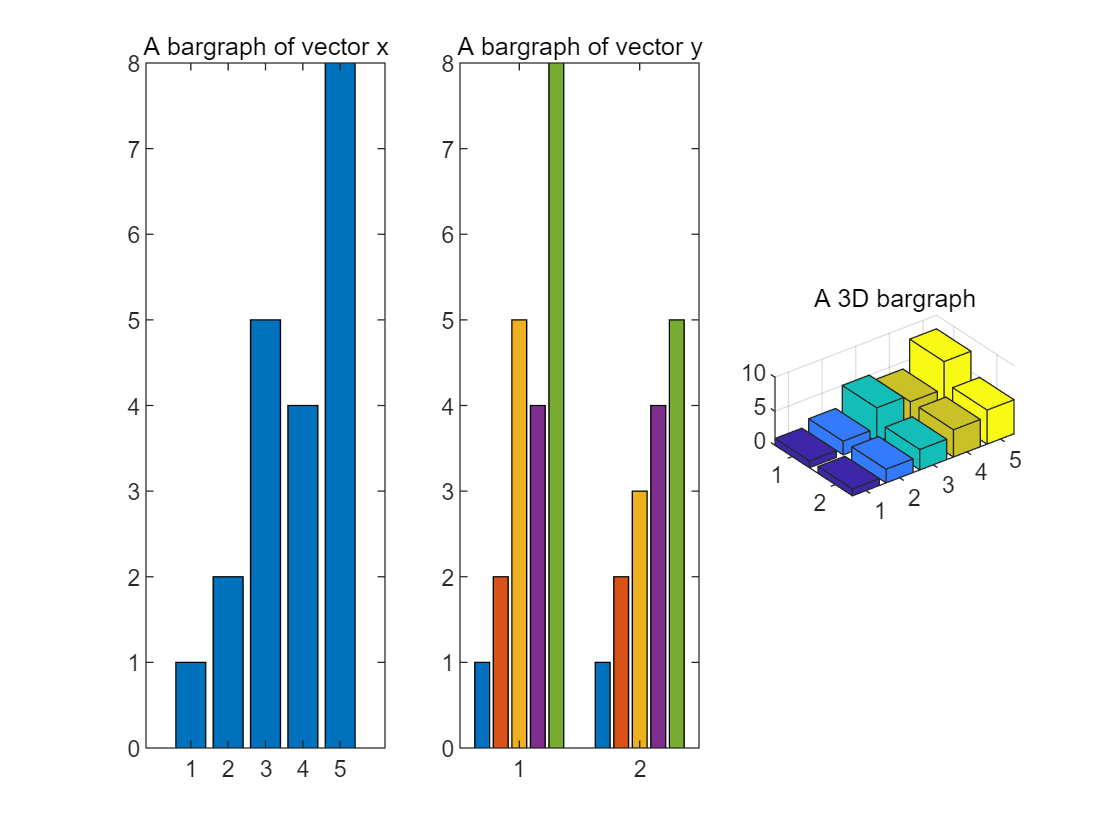

close all;
x = [1,2,5,4,8];
y = [x;1:5];
subplot(1,3,1);bar(x);title('A bargraph of vector x');
subplot(1,3,2);bar(y);title('A bargraph of vector y');
subplot(1,3,3);bar3(y);title('A 3D bargraph');

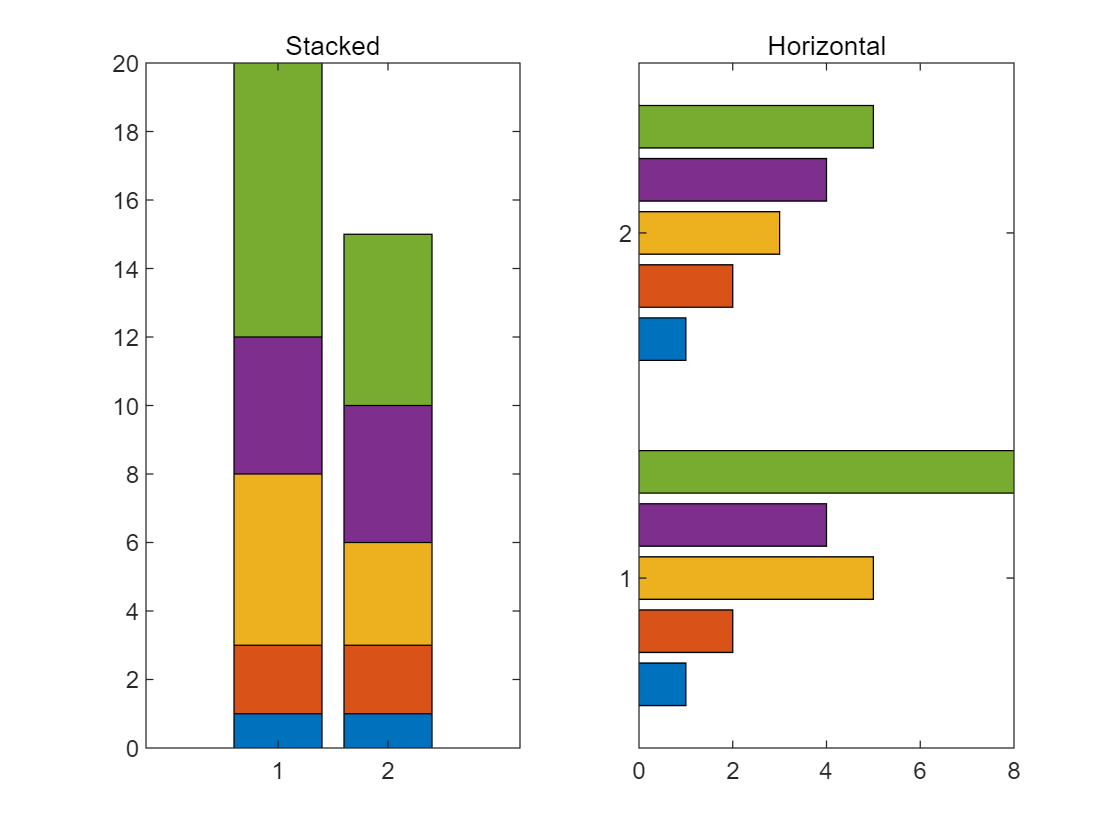

% bar(y,'stacked') 堆叠条形图
% barh(y) 横向条形图
close all;
x = [1,2,5,4,8];
y = [x;1:5];
subplot(1,2,1);
bar(y,'stacked');
title('Stacked');
subplot(1,2,2);
barh(y);
title('Horizontal');

## 饼状图 pie

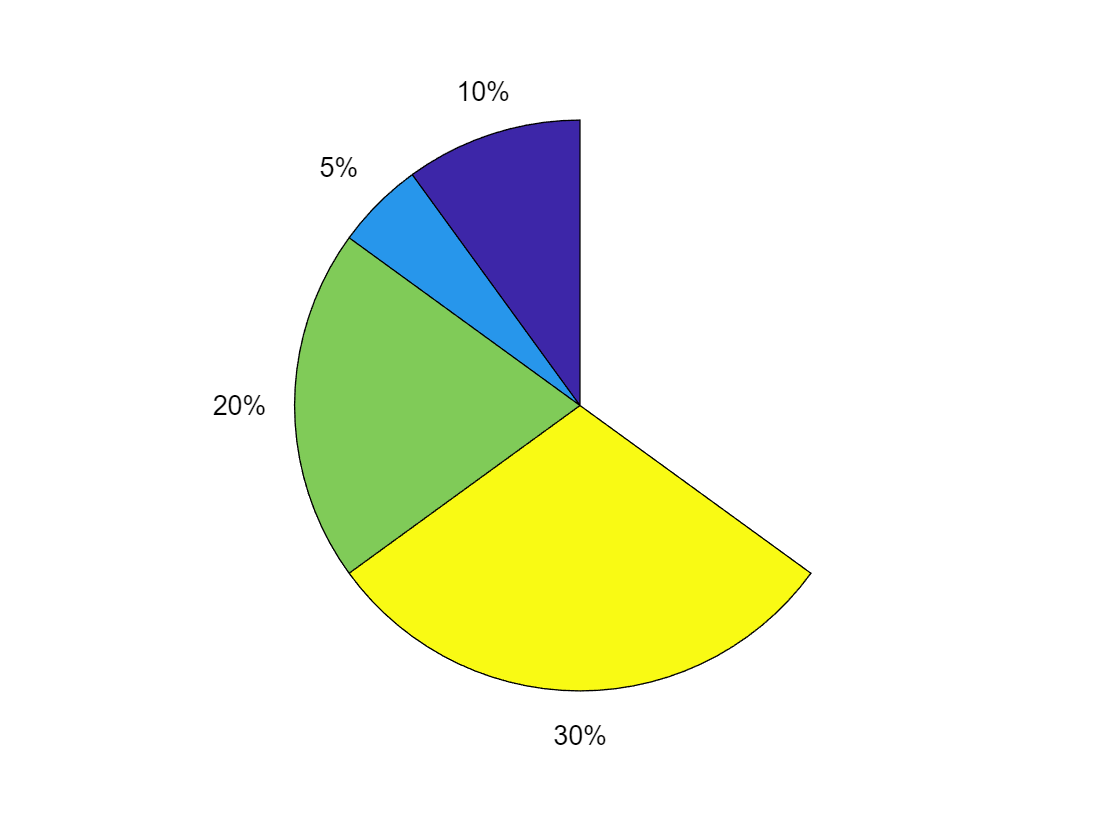

close all;
% 如果sum(x) ≤ 1 x 中的值直接指定饼图扇区的面积；
% 如果sum(x) < 1 pie 仅绘制部分饼图；
% 如果sum(x) > 1 ，则 pie 通过 x/sum(x) 对值进行归一化，以确定饼图的每个扇区的面积
a = [0.1,0.05,0.2,0.3];
pie(a);

### 一些较为复杂的饼图绘制例子

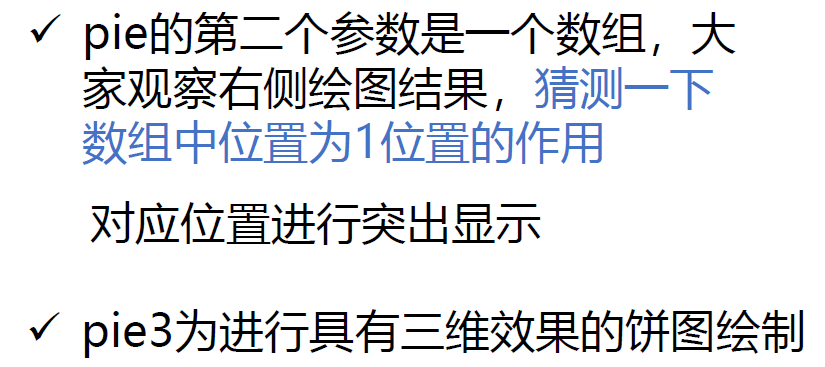

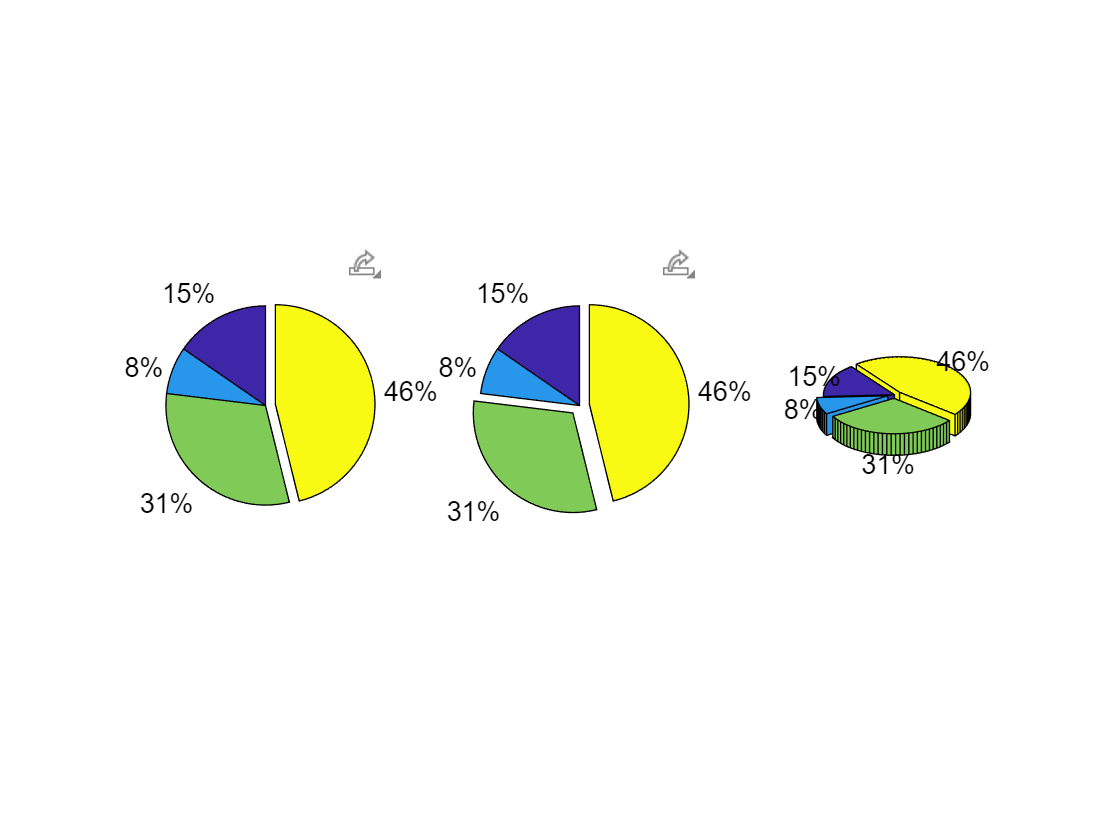

close all;
a = [10,5,20,30];
subplot(1,3,1);pie(a,[0,0,0,1]); % [0,0,0,1]表示30那一块往外画
subplot(1,3,2);pie(a,[0,0,1,1]);
subplot(1,3,3);pie3(a,[0,1,1,1]);

## 极坐标图 polar

**polarplot(theta,rho)在极坐标中绘制线条，theta表示弧度角，rho表示每个点的半径值**

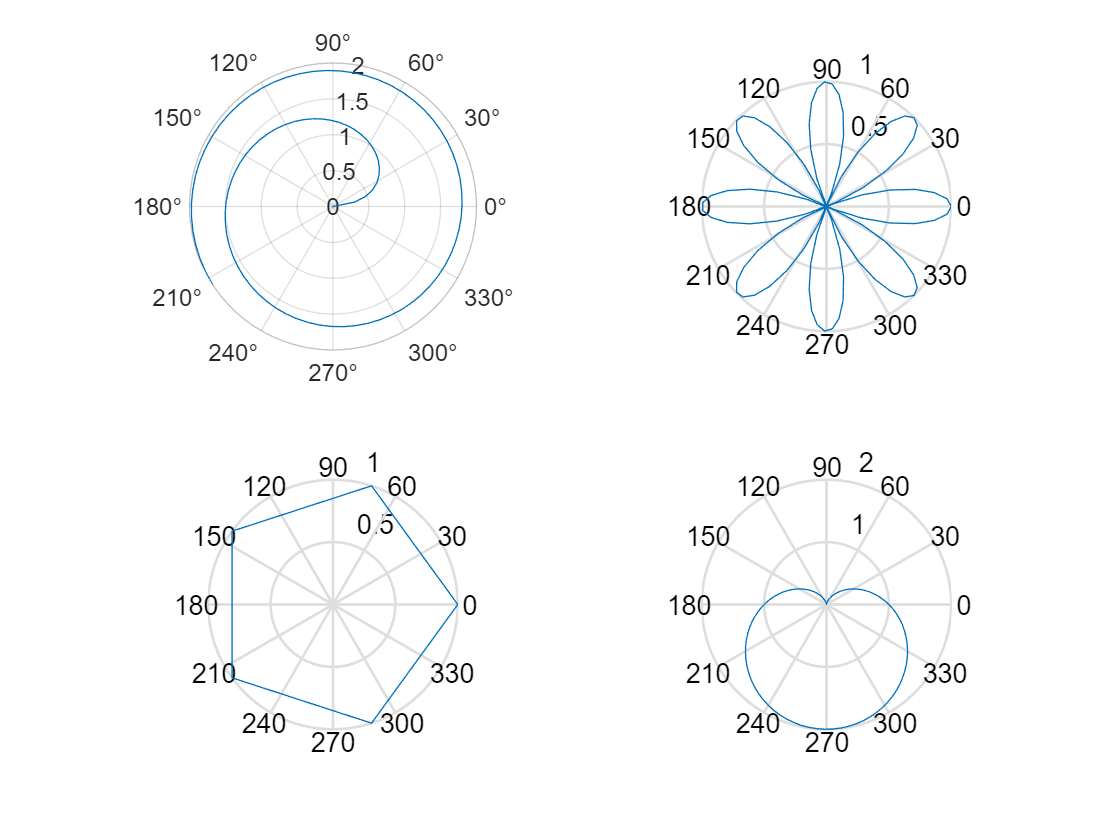

close all;
x = 1:100;theta = x/10;r = log10(x);subplot(2,2,1);polarplot(theta,r);
theta = linspace(0,2*pi);r = cos(4*theta);subplot(2,2,2);polar(theta,r);
theta = linspace(0,2*pi,6);r = ones(1,length(theta));subplot(2,2,3);polar(theta,r);
theta = linspace(0,2*pi);r = 1-sin(theta);subplot(2,2,4);polar(theta,r);

## 离散数据图：阶梯图和火柴杆图 stairs和stem

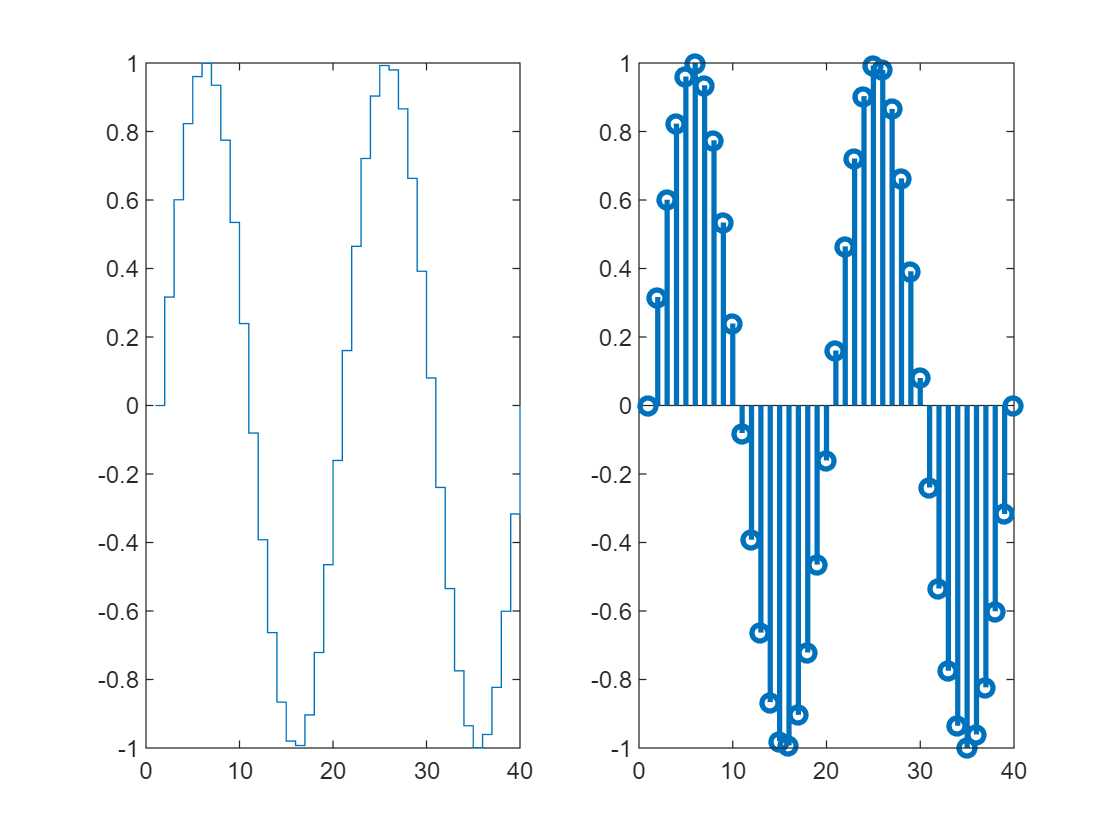

close all;
x = linspace(0,4*pi,40);
y = sin(x);
subplot(1,2,1);stairs(y);
subplot(1,2,2);stem(y,"LineWidth",2);

## 误差棒图 errorbar

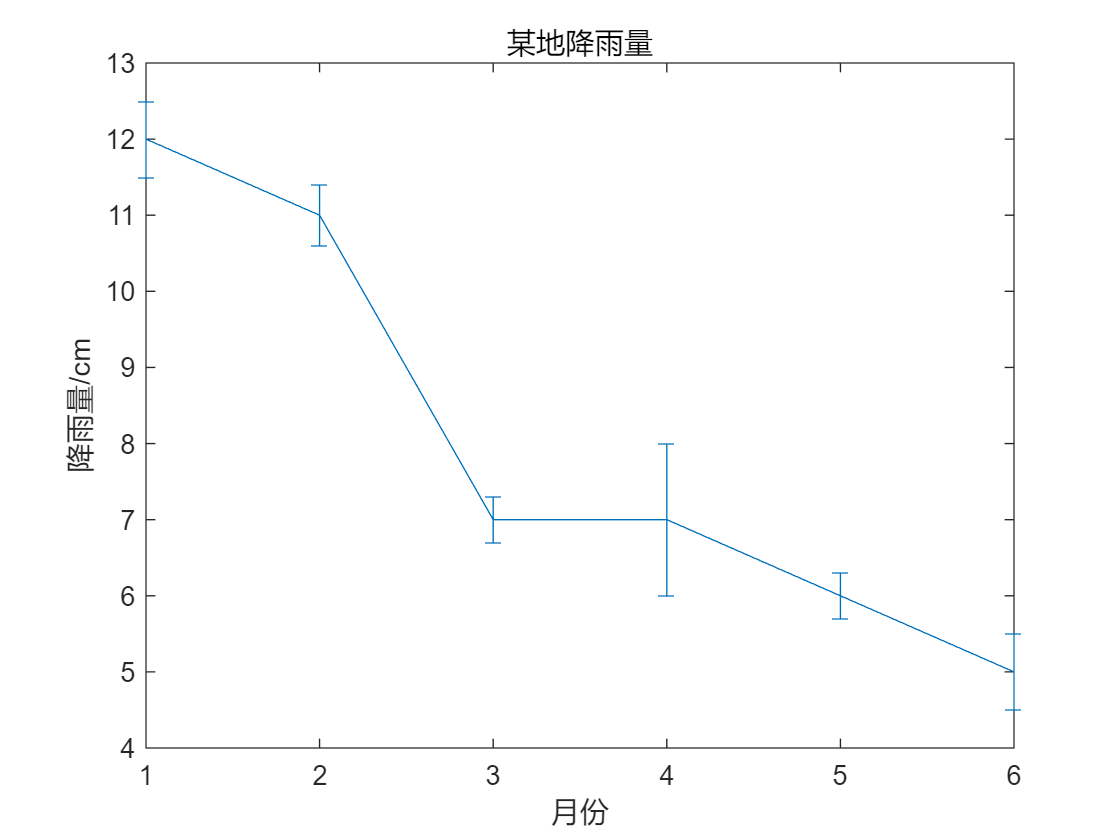

close all;
% 一般形式：先给出平均值，再给方差标准差调用 errorbar 进行绘制
Time = 1:1:6;
Average = [12,11,7,7,6,5]; % 各月的平均气温
Variance = [0.5,0.4,0.3,1,0.3,0.5]; % 各月的方差值
errorbar(Time,Average,Variance); % 调用格式 errorbar(A,B,X)
xlabel('月份');ylabel('降雨量/cm');
title('某地降雨量');

## 盒图 boxplot

修《概率论与数理统计》的时候学习过

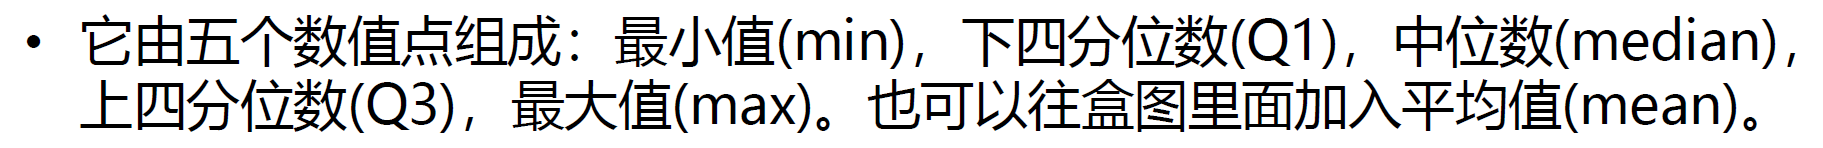

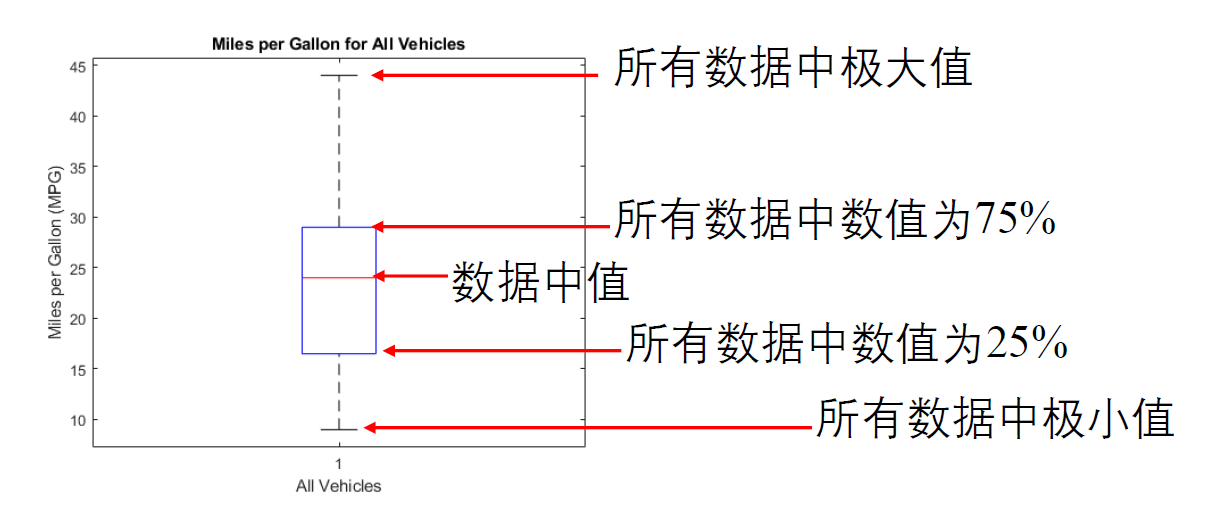

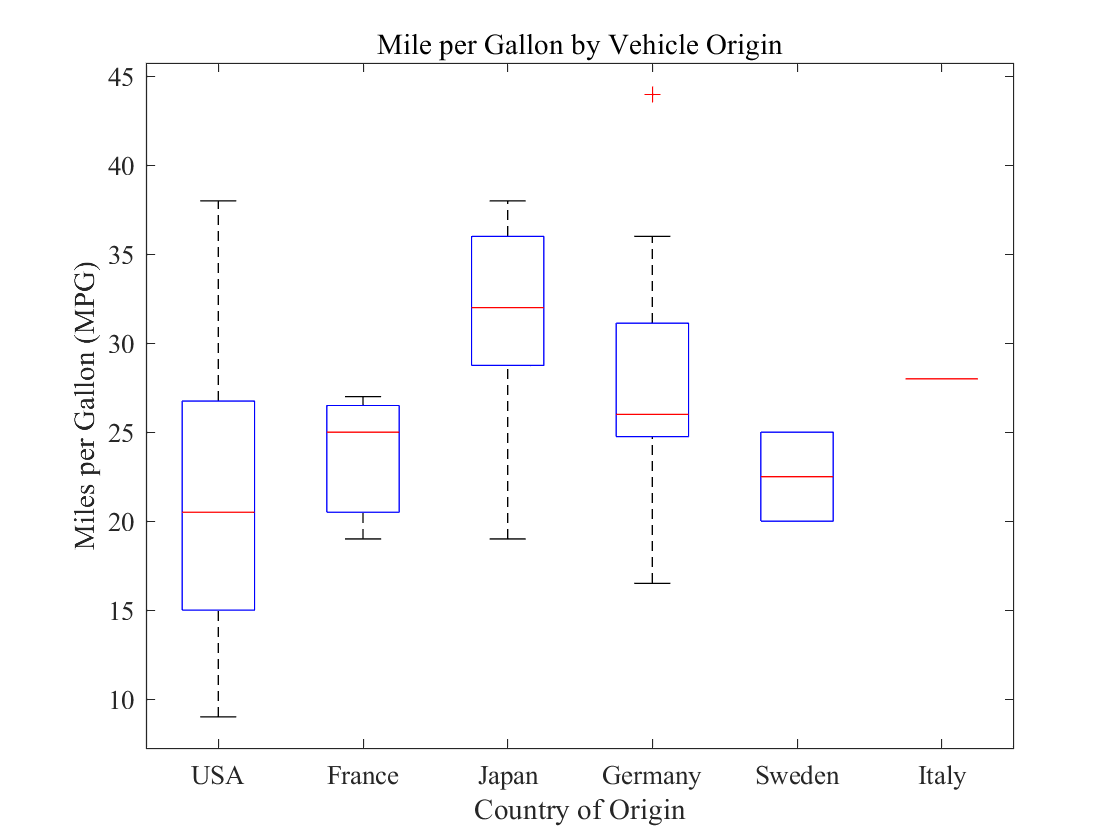

% 加载自带的一个数据库
close all;
load carsmall;
boxplot(MPG,Origin);
title('Mile per Gallon by Vehicle Origin');
xlabel('Country of Origin');
ylabel('Miles per Gallon (MPG)');
set(gca,"FontName","Times New Roman");

## 等高线图 contour

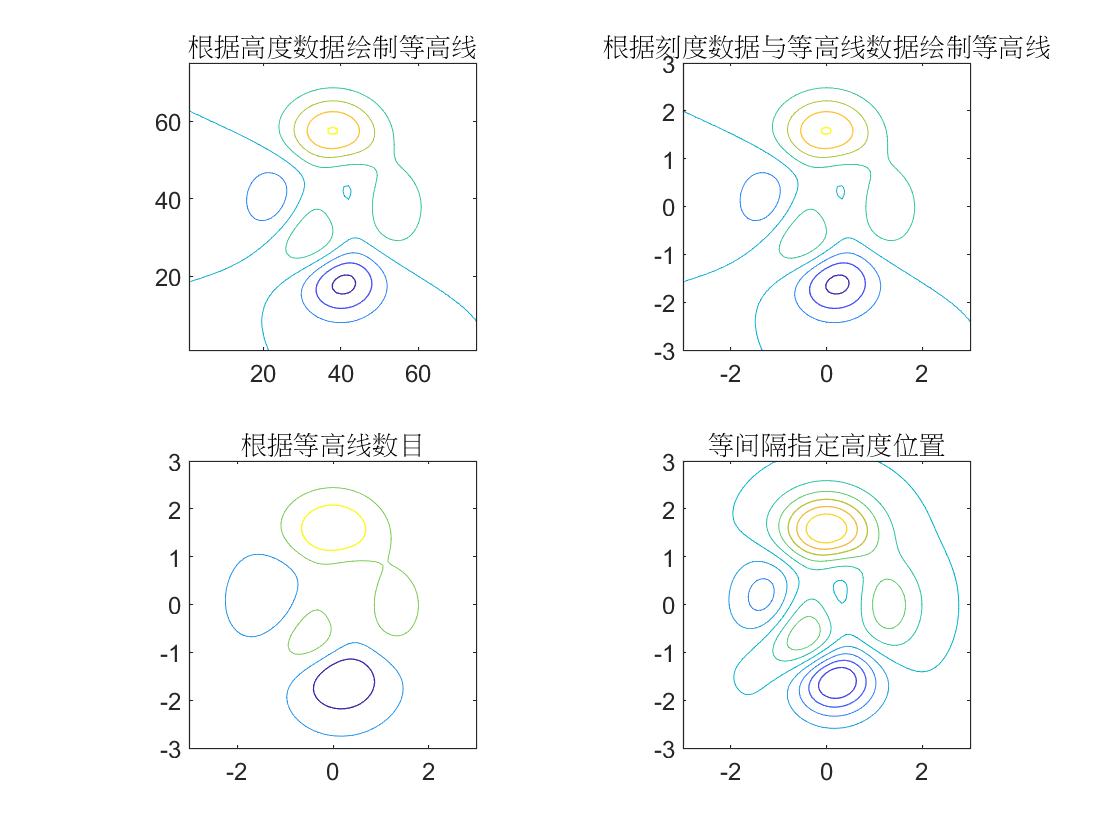

close all;
% 先给出数据(peaks)
set(gca,"FontName","Times New Roman");
[x,y,z] = peaks(75); % 生成坐标刻度数据和高度数据
s(1) = subplot(221);
contour(z);
title('根据高度数据绘制等高线');
s(2) = subplot(222);
contour(x,y,z);
title('根据刻度数据与等高线数据绘制等高线');
s(3) = subplot(223);
contour(x,y,z,4);
title('根据等高线数目');
s(4) = subplot(2,2,4);
contour(x,y,z,linspace(min(z(:)),max(z(:)),12));
title('等间隔指定高度位置');
axis(s,'square'); % 设置所有坐标轴为方形